# Machine Learning with MATLAB

## Statistical and Machine Learning Toolbox

[https://www.mathworks.com/products/statistics.html](https://www.mathworks.com/products/statistics.html)

Statistics and Machine Learning Toolbox™ provides functions and apps to describe, analyze, and model data. 

It provides tools and algorithms for:

- descriptive statistics, visualizations, and clustering for exploratory data analysis

- principal component analysis (PCA), regularization, dimensionality reduction, and feature selection methods for multidimensional data analysis and feature extraction

- supervised, semi-supervised, and unsupervised machine learning methods, including support vector machines (SVMs), boosted decision trees, k-means, and other clustering methods

- ... ...

**Install Toolbox:**

Add-Ons --> Get Add-Ons --> search for the toolbox --> install

[**Machine Learning Onramp**](http://matlabacademy.mathworks.com/selfpaced/machinelearning) is a two-hour course as a nice introduction.

### Some useful functions in data preprocessing

#### Import and Process Data

- The [`readtable`](http://www.mathworks.com/help/matlab/ref/readtable.html) function creates a table in MATLAB from a data file.

- The [`categorical`](https://www.mathworks.com/help/matlab/ref/categorical.html) function creates a categorical array from data.

- Assigning the empty array removes rows or columns. The [`rmmissing`](https://www.mathworks.com/help/matlab/ref/rmmissing.html) function removes any row with missing or undefined elements.

- The [`groupsummary`](https://www.mathworks.com/help/matlab/ref/double.groupsummary.html) function calculates statistics grouped according to a grouping variable.

- The [`innerjoin`](https://www.mathworks.com/help/matlab/ref/innerjoin.html) function merges two tables, retaining only the common key variable observations.

#### Visualize and Engineer Features

- The [`boxplot`](https://www.mathworks.com/help/stats/boxplot.html) function can create separate box plots based on a grouping variable.

- Indexing and element-wise division can be used to scale variables in a table.

- The [`gscatter`](https://www.mathworks.com/help/stats/gscatter.html) function creates a grouped scatter plot.

G = repelem(1:5,20); % repeat copies of array element
X = sin(G)+randn(1,numel(G));
Y = normrnd(G,1); % get normal random numbers
figure
gscatter(X,Y,G)

**Many functions can be used to calculate summary statistics: **

Measures of Central Tendency

- [`mean`](https://www.mathworks.com/help/matlab/ref/mean.html) Arithmetic mean

- [`median`](https://www.mathworks.com/help/matlab/ref/median.html) Median (middle) value

- [`mode`](https://www.mathworks.com/help/matlab/ref/mode.html) Most frequent value

- [`trimmean`](https://www.mathworks.com/help/stats/trimmean.html) Trimmed mean (mean, excluding outliers)

- [`geomean`](https://www.mathworks.com/help/stats/geomean.html) Geometric mean

- [`harmean`](https://www.mathworks.com/help/stats/harmmean.html) Harmonic mean

Measures of Spread

- [`range`](https://www.mathworks.com/help/stats/range.html) Range of values (largest – smallest)

- [`std`](https://www.mathworks.com/help/matlab/ref/std.html) Standard deviation

- [`var`](https://www.mathworks.com/help/matlab/ref/var.html) Variance

- [`mad`](https://www.mathworks.com/help/stats/mad.html) Mean absolute deviation

- [`iqr`](https://www.mathworks.com/help/stats/prob.normaldistribution.iqr.html) Interquartile range (75th percentile minus 25th percentile)

Measures of Shape

- [`skewness`](https://www.mathworks.com/help/stats/skewness.html) Skewness (third central moment)

- [`kurtosis`](https://www.mathworks.com/help/stats/kurtosis.html) Kurtosis (fourth central moment)

- [`moment`](https://www.mathworks.com/help/stats/moment.html) Central moment of arbitrary order

Other useful functions:

- Finding peaks: `islocalmax, islocalmin`

- Correlation between signals: `corr `

**Automating Feature Extraction by custom preprocessing (extraction) functions and transformed datastore**

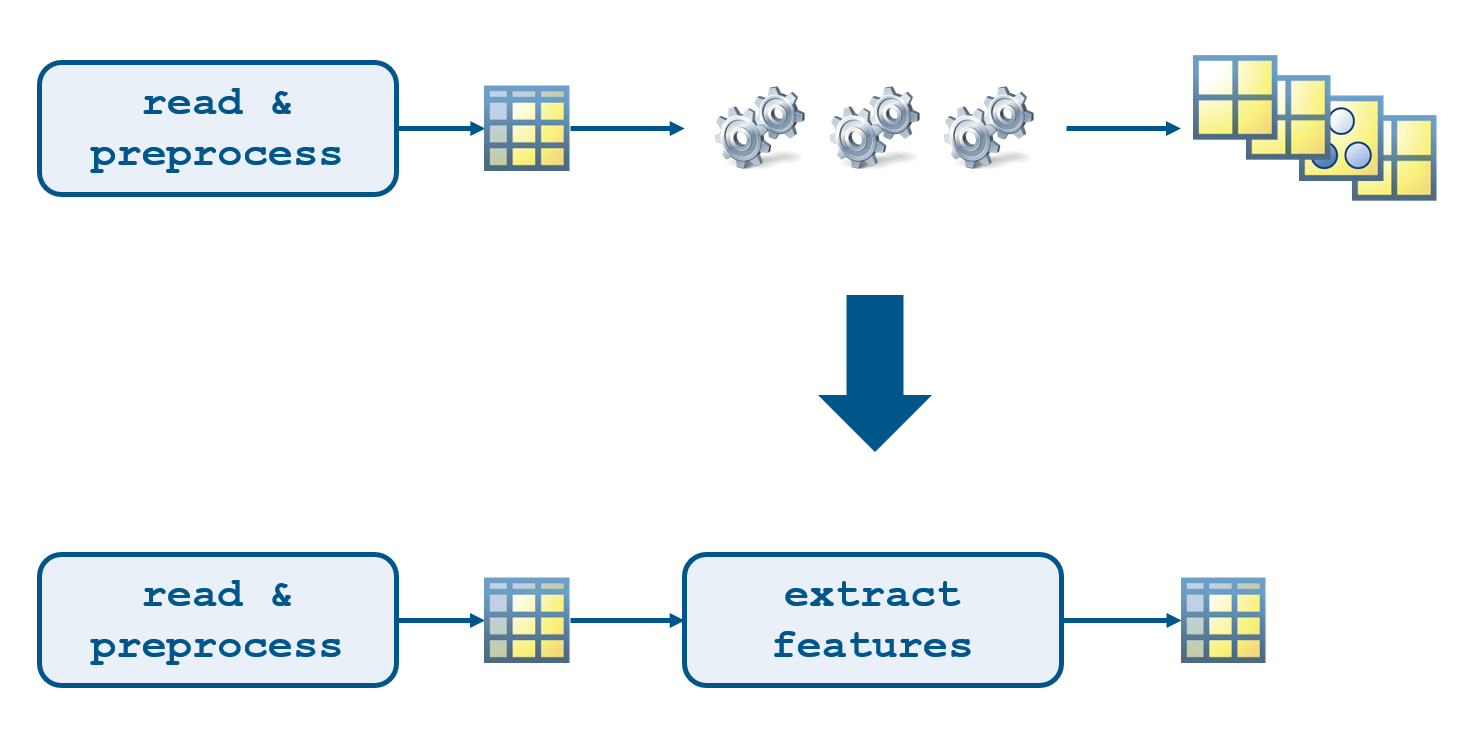

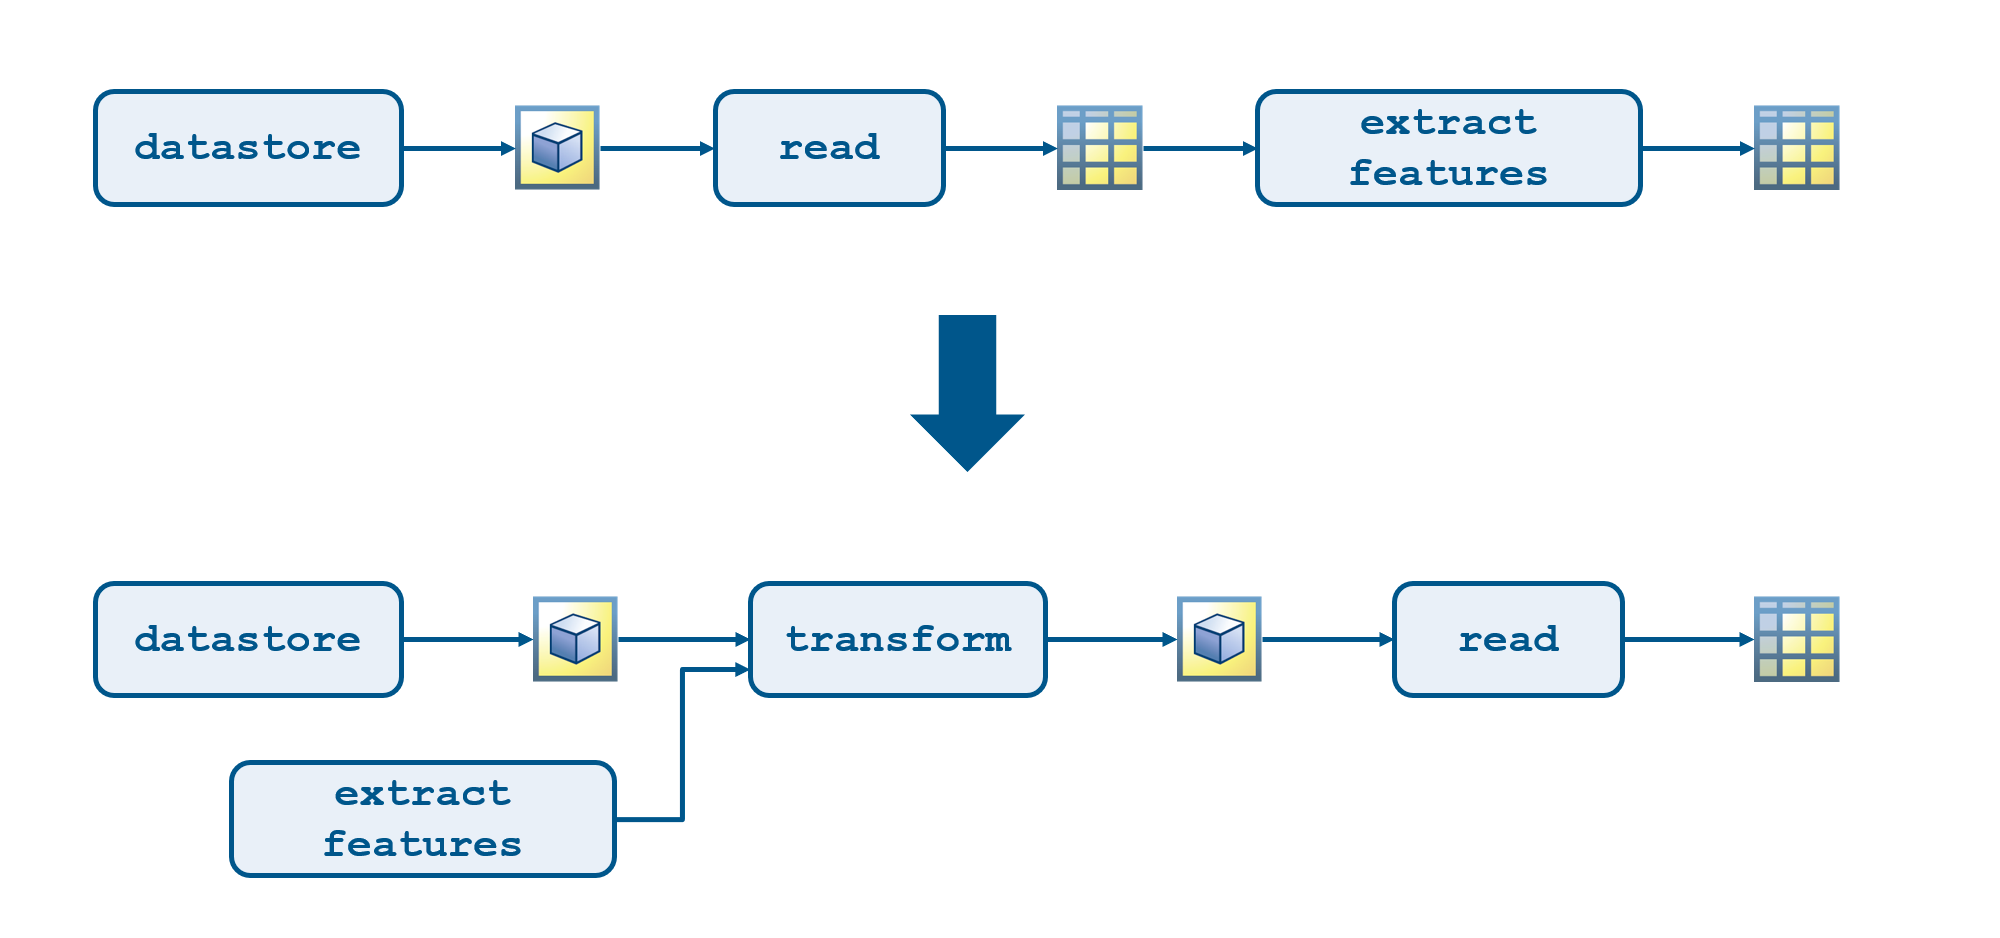

`dsnew = transform(ds1,ds2,...,dsN,@fcn)`

The transformation function `fcn` can be placed before or after all of the input datastores in the call to the `transform` function.

## Unsupervised Learning

Finding Natural Patterns in Data

### Demo: Grouping Basketball Players

Read file of basketball player data containing per game statistics.

data = readtable("data/basketballDataProcessed.csv");
posnames = ["G","G-F","F-G","F","F-C","C-F","C"];
data.pos = categorical(data.pos,posnames);

data.Properties.VariableNames

ans = 1×20 cell array
    {'Name'}    {'pos'}    {'GP'}    {'height'}    {'weight'}    {'minutes'}    {'points'}    {'oRebounds'}    {'dRebounds'}    {'assists'}    {'steals'}    {'blocks'}    {'turnovers'}    {'PF'}    {'fgAttempted'}    {'fgMade'}    {'ftAttempted'}    {'ftMade'}    {'threeAttempted'}    {'threeMade'}


summary(data)


Variables:

    Name: 1112×1 cell array of character vectors

    pos: 1112×1 categorical

        Values:

            G       367 
            G-F      99 
            F-G      49 
            F       316 
            F-C     118 
            C-F      44 
            C       119 

    GP: 1112×1 double

        Values:

            Min        100
            Median     389
            Max       1335

    height: 1112×1 double

        Values:

            Min          63   
            Median       79   
            Max          91   

    weight: 1112×1 double

        Values:

            Min         130   
            Median      215   
            Max         303   

    minutes: 1112×1 double

        Values:

            Min        4.8951  
            Median     21.143  
            Max        41.123  

    points: 1112×1 double

        Values:

            

**Visualize data**:

scatter plot with histogram

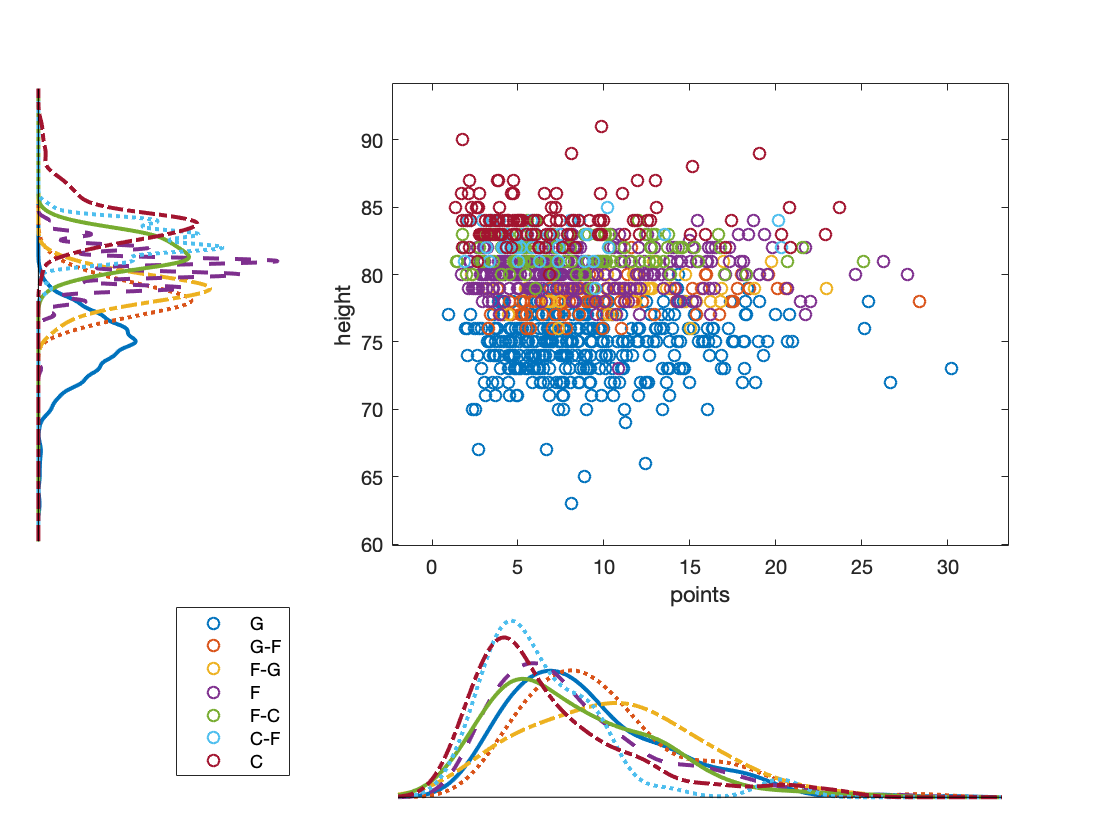

figure
s = scatterhist(data.points, data.height,'Group',data.pos,'Kernel','on');
xlabel("points"); ylabel("height"); 

correlation heatmap

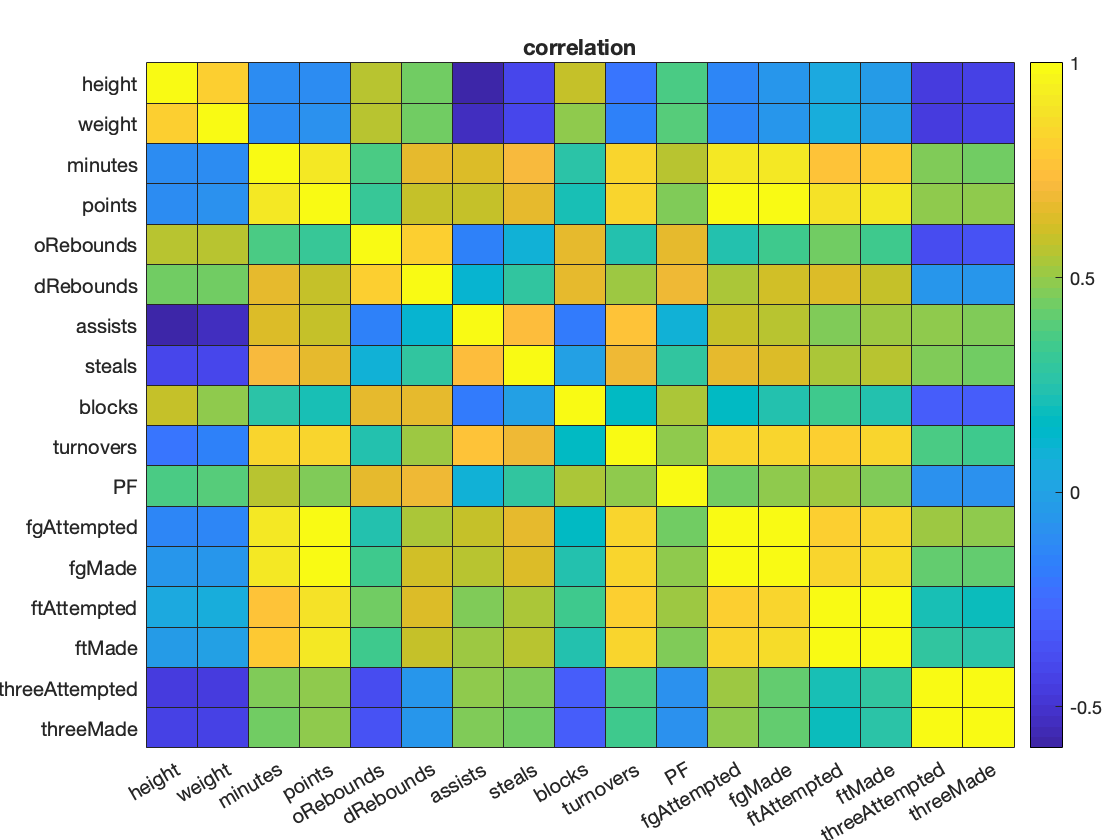

h = heatmap(corr(data{:,4:end}),'Colormap', parula);
h.XDisplayLabels = data.Properties.VariableNames(4:end);
h.YDisplayLabels = data.Properties.VariableNames(4:end);
h.Title = "correlation";

*Still hard to identify patterns or groups.*

Extract numeric data (and their names) and normalize data to mean 0 and standard deviation 1. Set random seed. 

labels = data.Properties.VariableNames(4:end);
stats = data{:,4:end};
statsNorm = normalize(stats);
rng(0)

#### Dimesionaltiy Reduction:

**Multidimensional Scaling (MDS)**

- Calculate pairwise distances `D` `=` `pdist``(data,"distance")`

- Perform multidimensional scaling` [x,e] = cmdscale(D)`

- `X `*m*-by-*q* matrix of the reconstructed coordinates in *q*-dimensional space. *q* is the minimum number of dimensions needed to achieve the given pairwise distances.

- `e `Eigenvalues of the matrix `x``*``x``'`.

d = pdist(statsNorm);
[X,e] = cmdscale(d);

**Principal Component Analysis (PCA)**

`[pcs,scrs,~,~,pexp] = pca(data)`

- `pcs `A *n*-by-*n* matrix of principal components.

- `scrs `An *m*-by-*n* matrix containing the data transformed using the linear coordinate transformation matrix `pcs` (first output).

- `pexp `A vector of length *n* containing the percentage of variance explained by each principal component.

[pcs,scrs,~,~,pexp] = pca(statsNorm);

**Compare PCA and CMD scaling**

Note that CMD scaling is the same as PCA when using the 2-norm as the distance metric (within a potential minus sign). In this case, it turns out that the 3rd component is flipped:

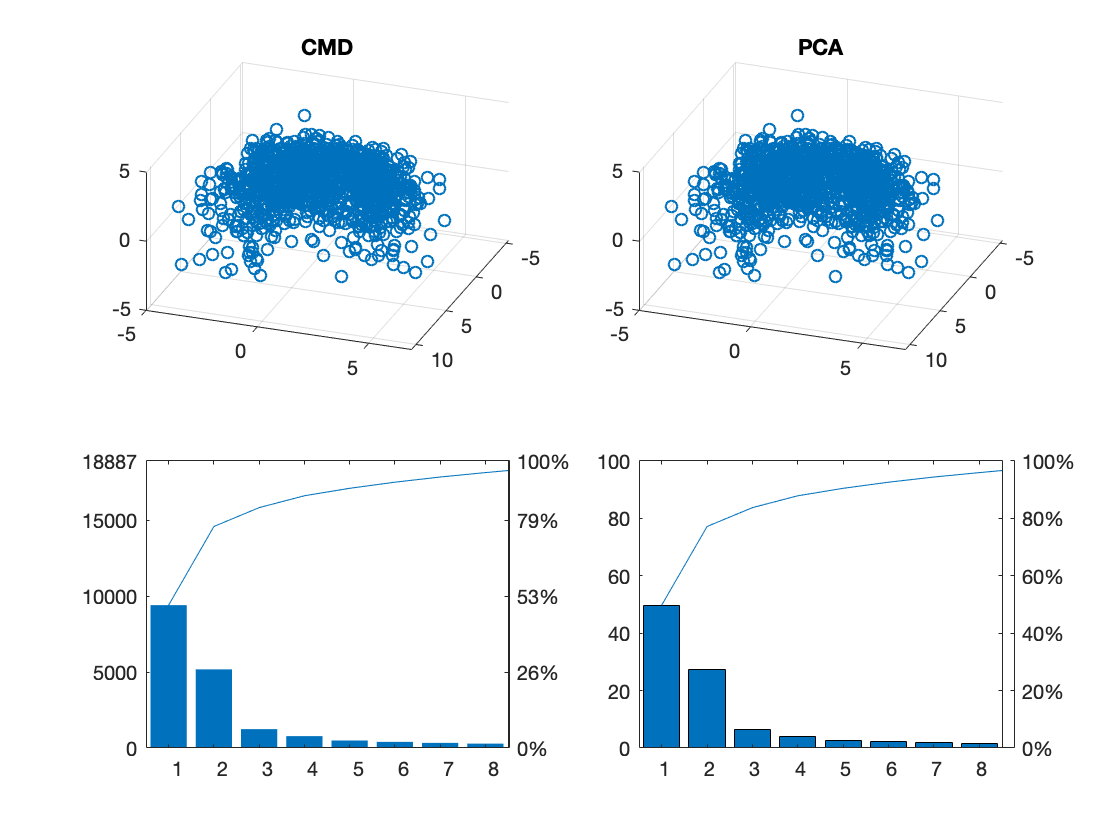

clf

% CMD scatter
subplot(2,2,1)
scatter3(X(:,1),X(:,2),-X(:,3))   % flip 3rd component
view(110,40)
title("CMD")

% PCA scatter
subplot(2,2,2)
scatter3(scrs(:,1),scrs(:,2),scrs(:,3))
view(110,40)
title("PCA")

% CMD pareto
subplot(2,2,3)
pareto(e)

% PCA pareto
subplot(2,2,4)
pareto(pexp)

Look for correlation with player position

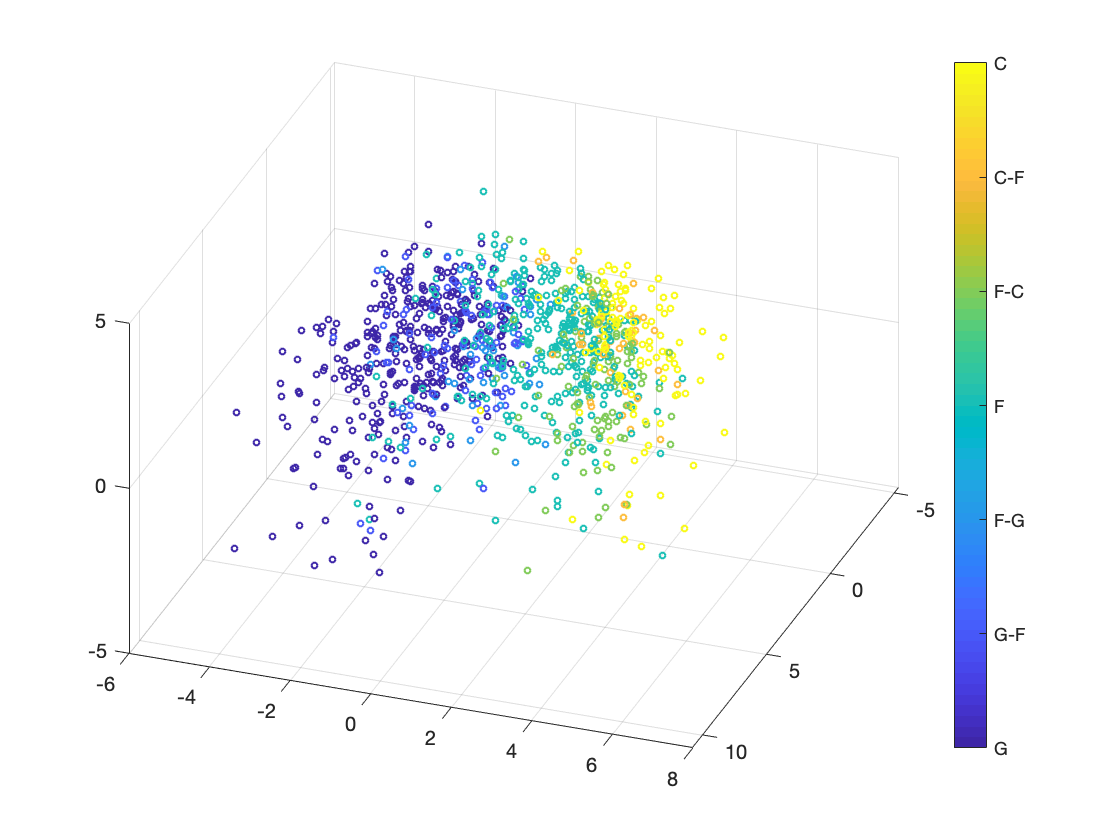

clf
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,data.pos)
view(110,40)
c = colorbar;
c.TickLabels = posnames;

#### Clustering Algorithms:

Cluster data into *k* groups using different methods and plot transformed (PCA) data by group for each method.

rng(0)
k = 3

k = 3

***k*****-means Clustering**

`idx = kmeans(X,k)`

- `X `Data, specified as a numeric matrix.

- `k `Number of clusters.

- `idx `Cluster indices, returned as a numeric column vector.

- optional inputs: `"Distance"-`Distance Metric, `"Start"-`Starting Locations of Cluster Centroids, `"Replicates"-`Replicates.

Perform k-means clustering

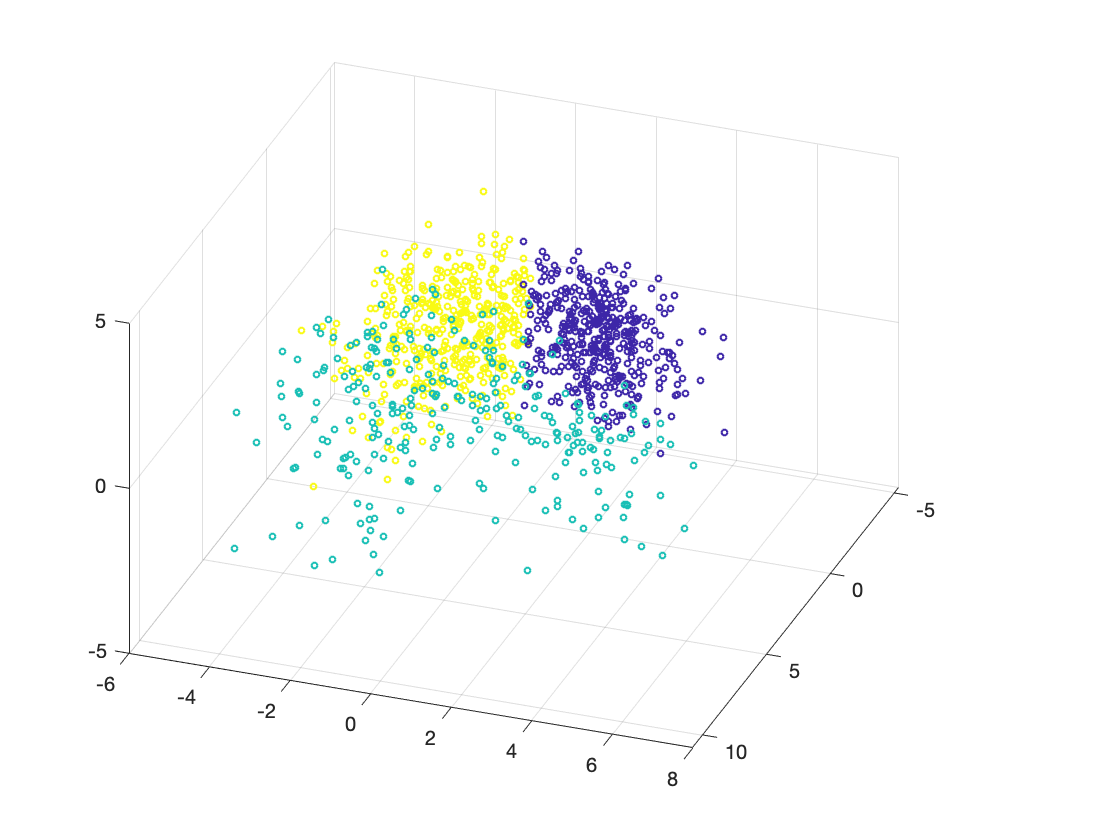

grpKM = kmeans(statsNorm,k,"Replicates",5);
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,grpKM)
view(110,40)

**Gaussian Mixture Models (GMM)**

GMM clustering involves fitting several *n*-dimensional normal distributions to the data, and using those distributions to assign each observation to a cluster.

- Fit Gaussian Mixture Model: `gm = fitgmdist(X,2); `

- Identify Clusters: `g = cluster(gm,X);[g,~,p] = cluster(gm,X);`

Fit a Gaussian mixture model

gmModel = fitgmdist(statsNorm,k,"Replicates",5,...
    "RegularizationValue",0.02,"Options",struct("MaxIter",200));

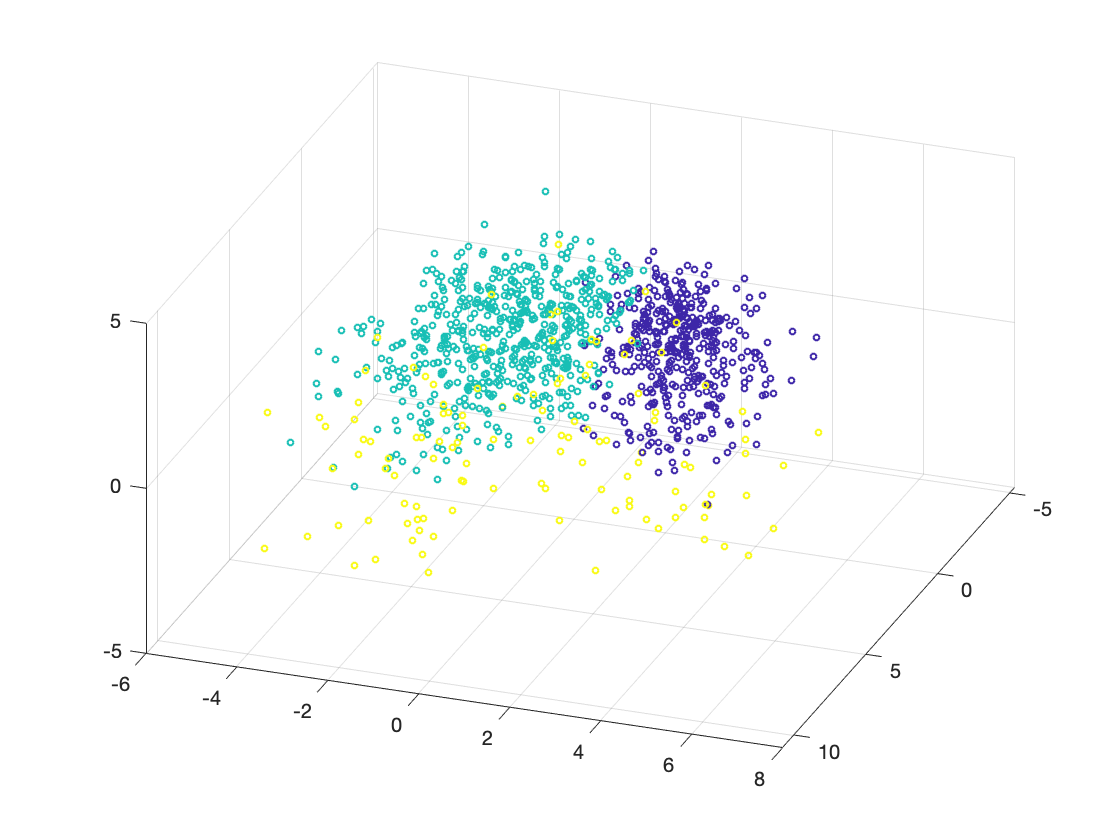

grpGM = cluster(gmModel,statsNorm);
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,grpGM)
view(110,40)

**Hierarchical Clustering**

With hierarchical clustering, we can explore the *sub-clusters* that were grouped together to form bigger clusters.

Determine Hierarchical Structure

- use the `linkage` function to create the hierarchical tree.

- use the `dendrogram` function to visualize the hierarchy.

Divide Hierarchical Tree into Clusters

- use the `cluster` function to assign observations into groups, according to the linkage distances `Z`.

`Z` `=` `linkage``(``X``,``"centroid"``,``"cosine"``)``;`

`dendrogram``(``Z``)`

`grp` `=` `cluster``(``Z``,``"maxclust"``,``3``)`

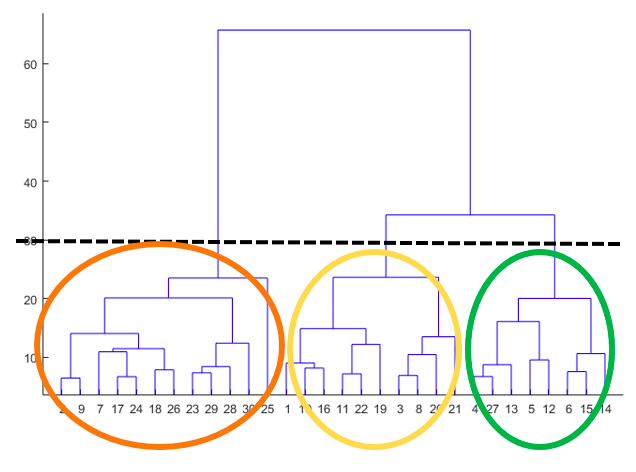

Perform hierarchical clustering

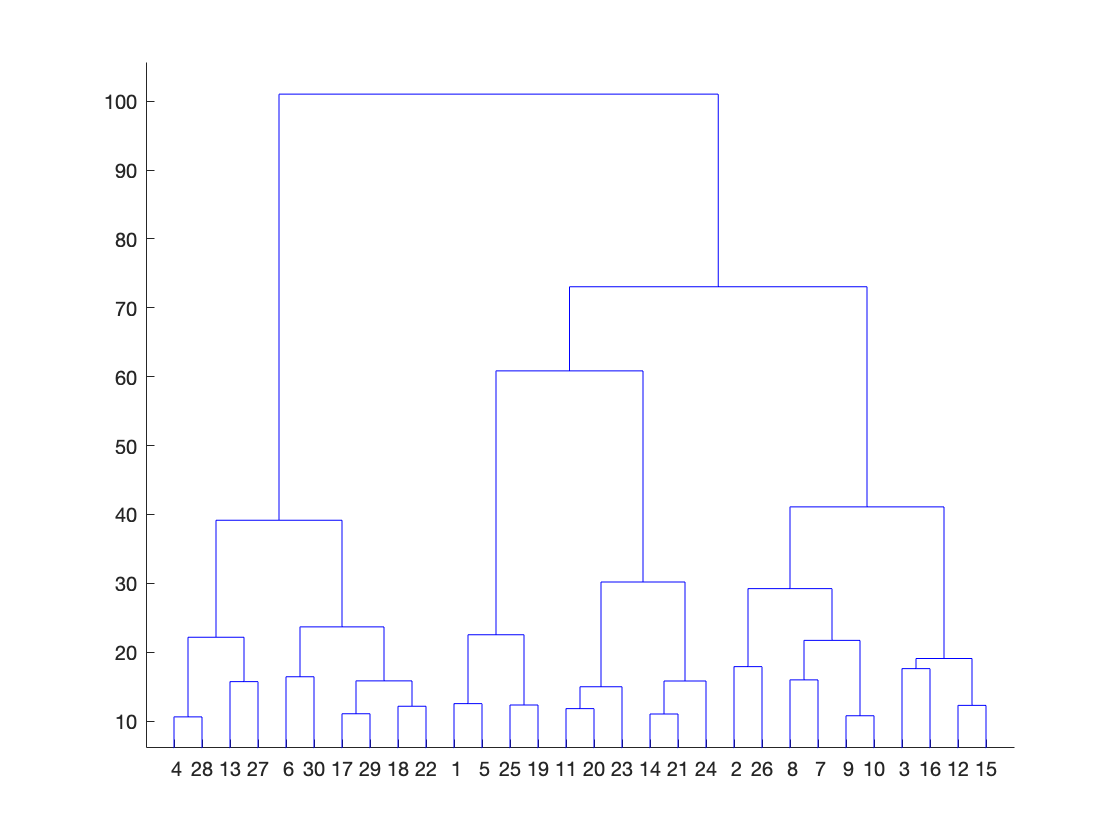

Z = linkage(statsNorm,"ward");
dendrogram(Z);

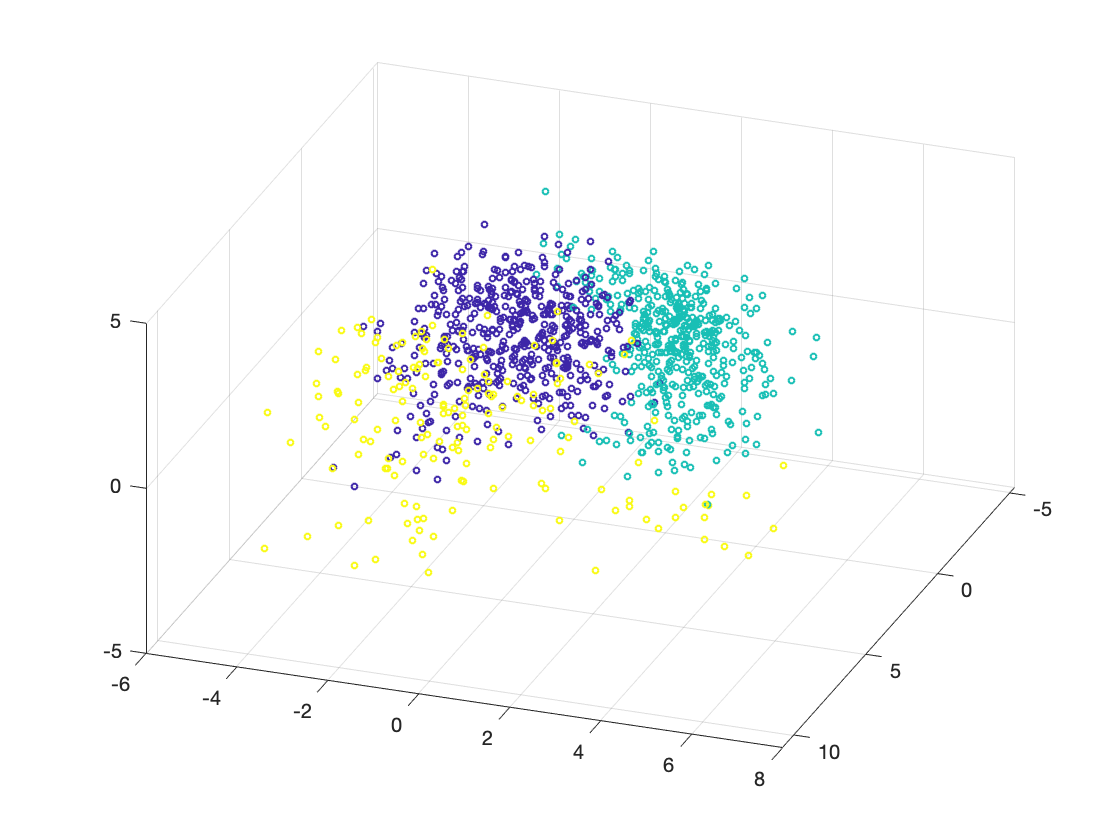

grpHC = cluster(Z,"maxclust",k);
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,grpHC)
view(110,40)

#### Interpret Clusters

Visualize group separation for GMM.

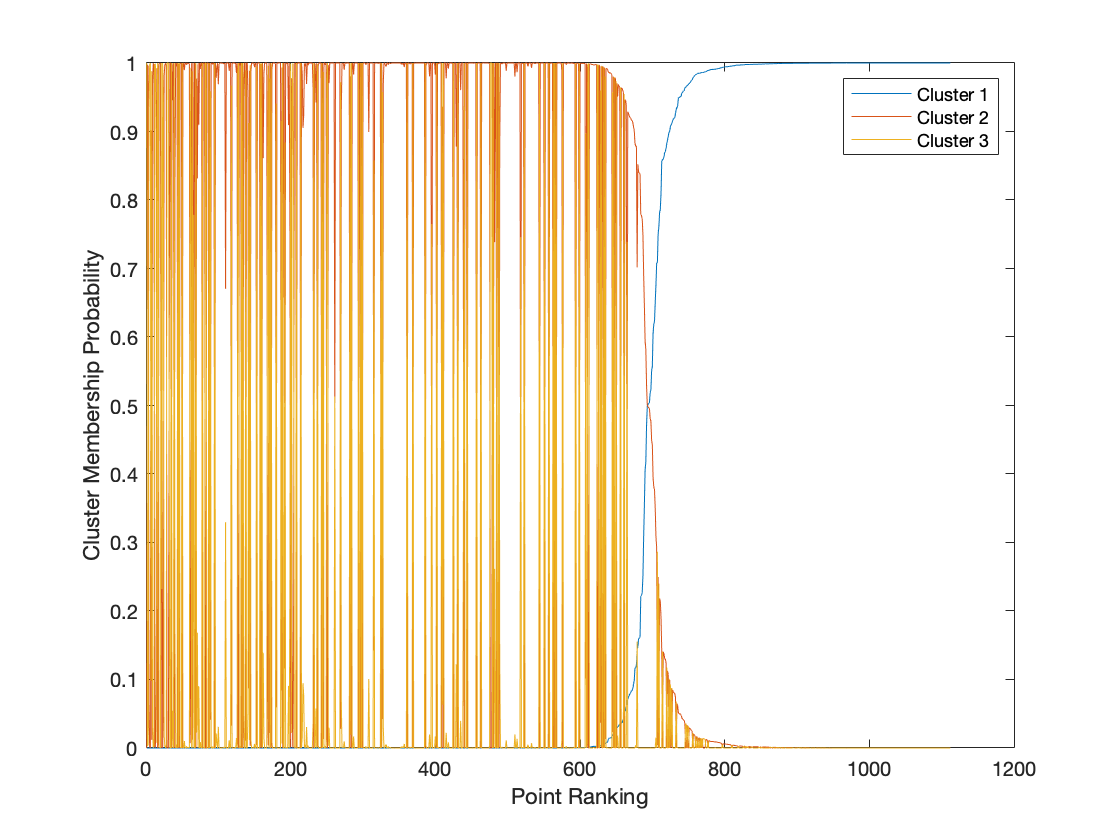

[grpGM,~,gprob] = cluster(gmModel,statsNorm);
gpsort = sortrows(gprob,1:k-1);
plot(gpsort)
xlabel("Point Ranking")
ylabel("Cluster Membership Probability")
legend("Cluster "+ (1:k))

Create a **silhouette plot**

The silhouette plot displays a measure of how close each point in one cluster is to points in the neighboring clusters and thus provides a way to assess parameters like number of clusters visually. 

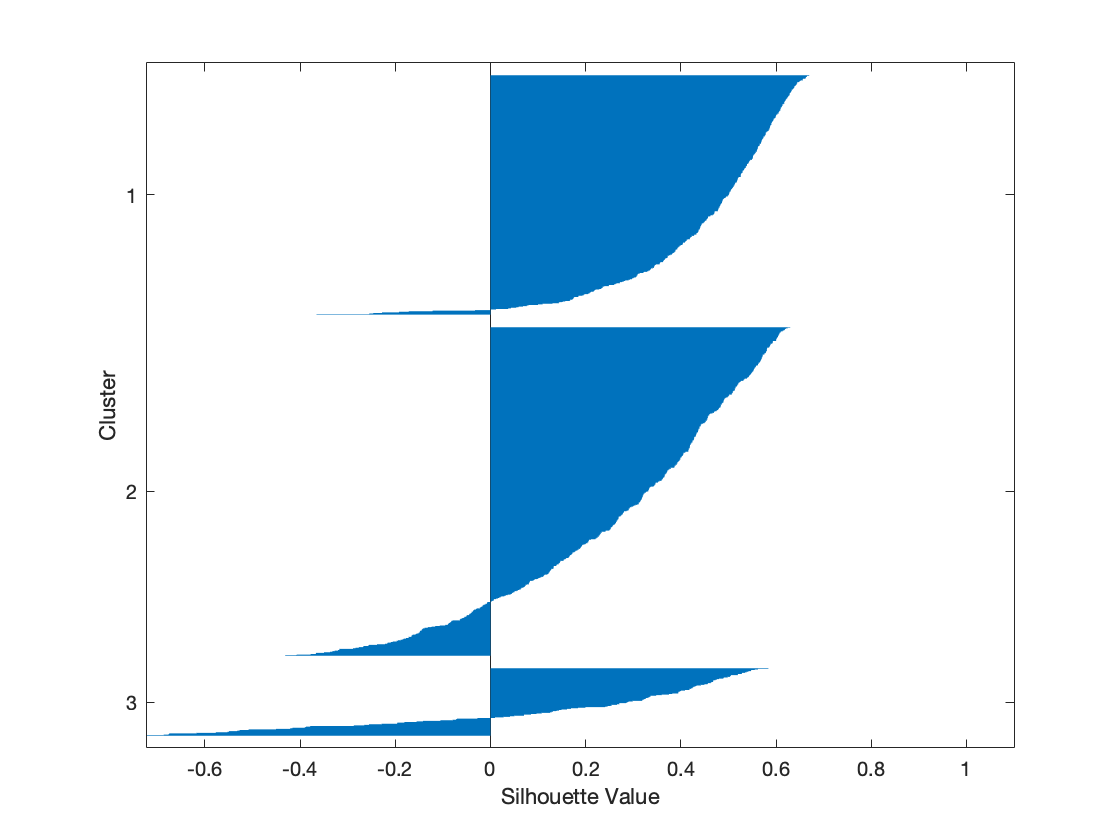

silhouette(statsNorm,grpGM)

Visualize cluster membership by position.

ct = crosstab(data.pos,grpGM)

ct =      0   335    32
     0    89    10
     6    38     5
   170   102    44
   104     5     9
    38     2     4
   101     4    14


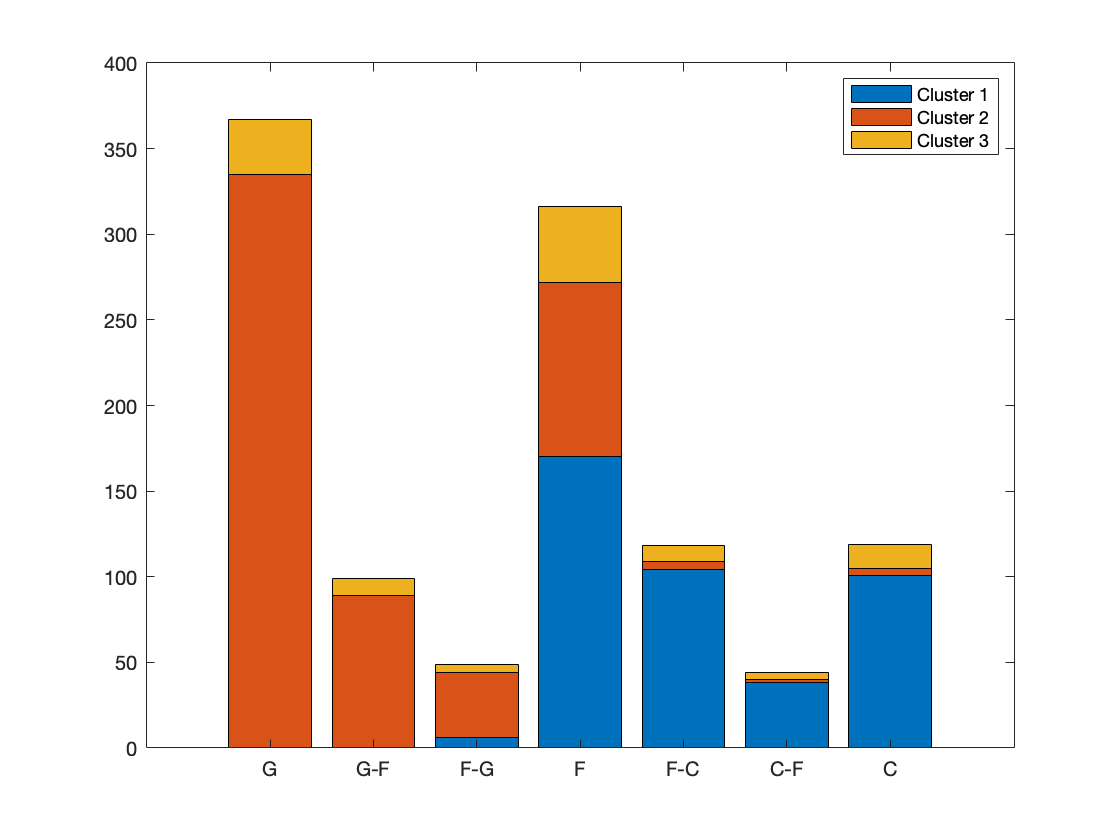

bar(ct,"stacked")
legend("Cluster "+ (1:k))
xticklabels(categories(data.pos))

Create parallel coordinates plot of group mean.

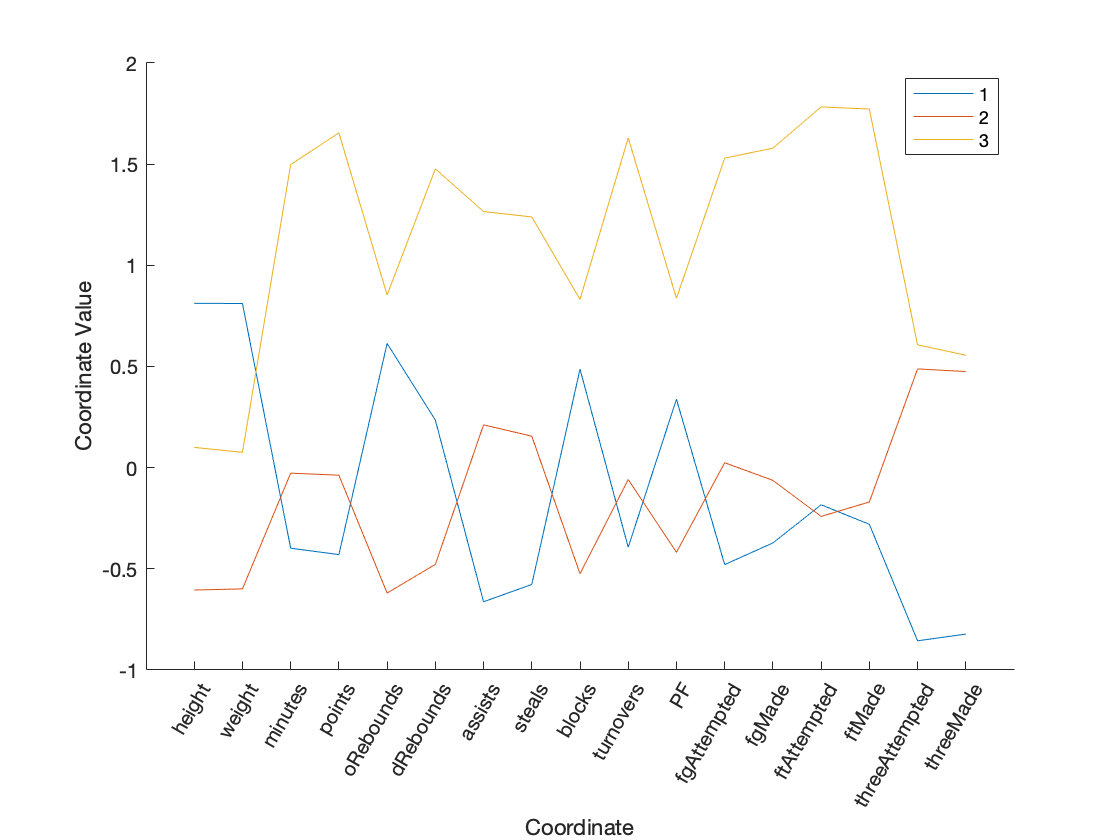

parallelcoords(gmModel.mu,"Group",1:k)
xticklabels(labels)
xtickangle(60)

Evaluate optimal number of clusters

cev = evalclusters(statsNorm,"gmdistribution","DaviesBouldin","KList",2:6)

cev =   DaviesBouldinEvaluation with properties:

    NumObservations: 1112
         InspectedK: [2 3 4 5 6]
    CriterionValues: [1.1693 1.4546 1.6066 1.9206 1.5790]
           OptimalK: 2


optK = cev.OptimalK

optK = 2

## Clusters within a Player Position

Extracts the data for the guard position (`G`). Can change to other positions.

posStats = statsNorm(data.pos == "G",:);

Create and visualize hierarchical tree.

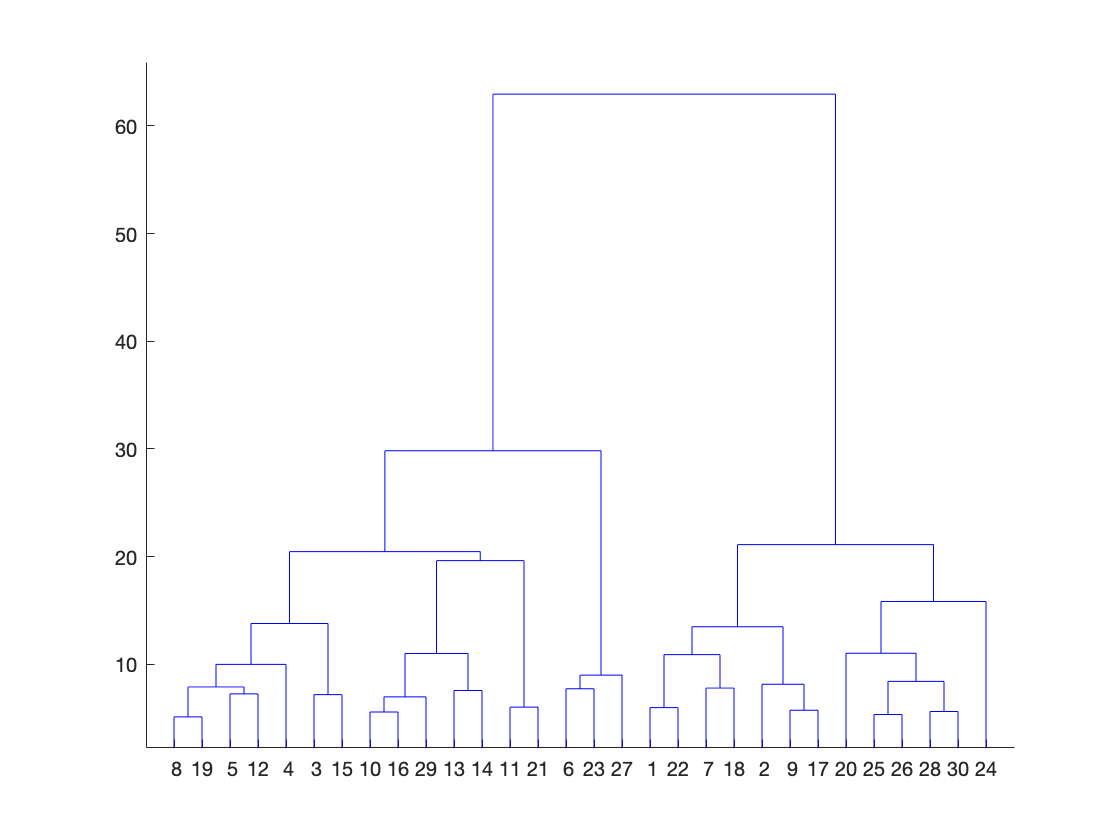

Z = linkage(posStats,"ward");
dendrogram(Z)

Cluster into 2 and 3 clusters.

gc2 = cluster(Z,"maxclust",2);
gc3 = cluster(Z,"maxclust",3);

Visualize clusters (middle 50% of each cluster)

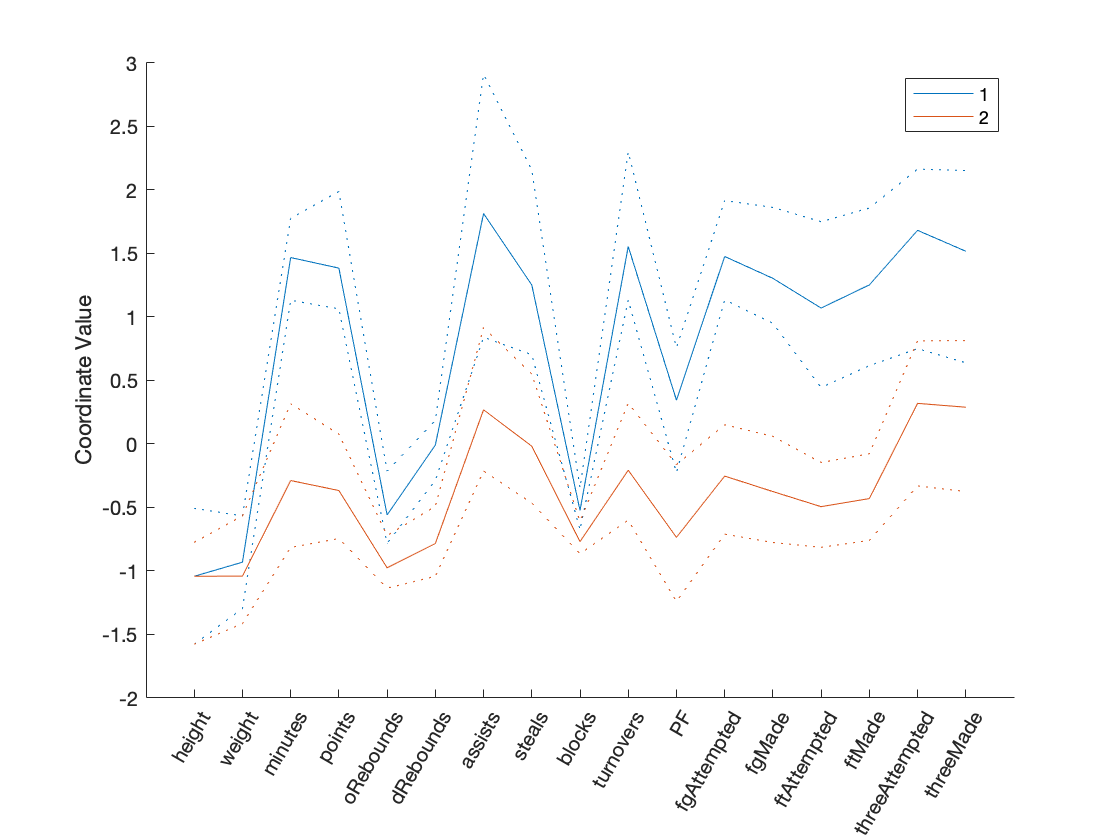

parallelcoords(posStats,"Group",gc2,"Quantile",0.25,"Labels",labels)
xtickangle(60)

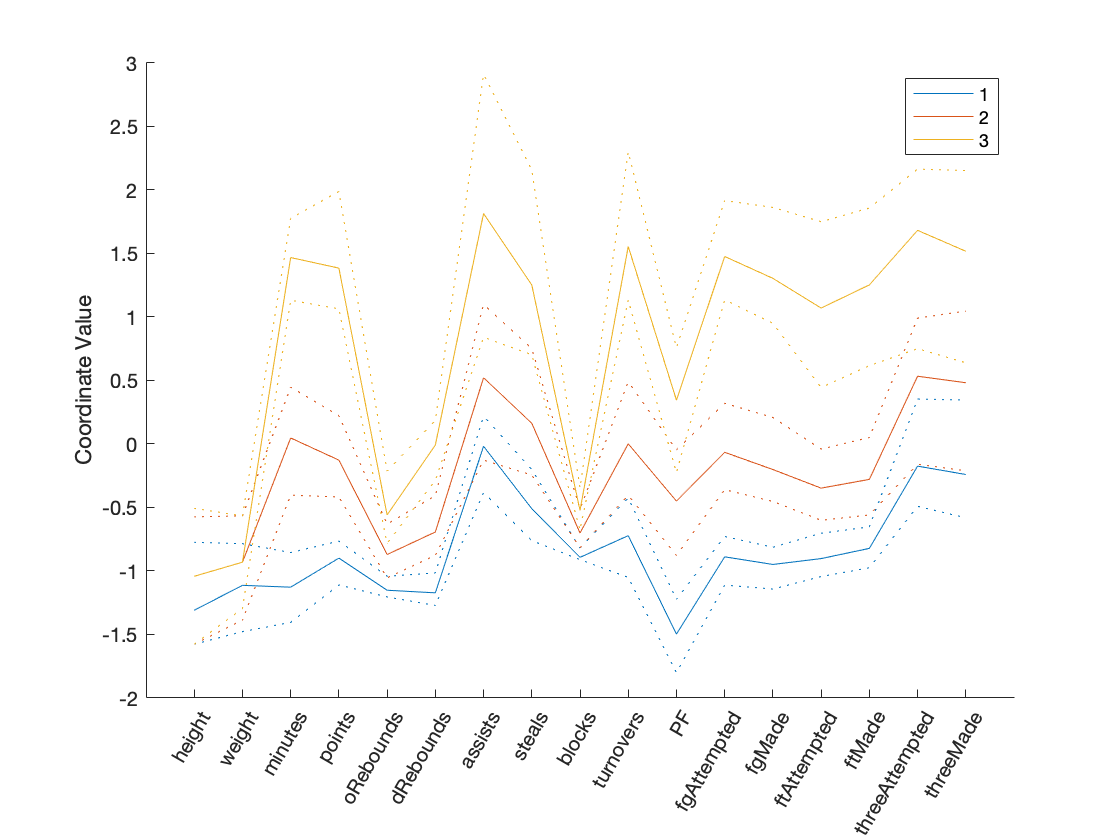

parallelcoords(posStats,"Group",gc3,"Quantile",0.25,"Labels",labels)
xtickangle(60)

Evaluate optimal number of clusters.

ec = evalclusters(posStats,"linkage","silhouette","KList",2:8)

ec =   SilhouetteEvaluation with properties:

    NumObservations: 367
         InspectedK: [2 3 4 5 6 7 8]
    CriterionValues: [0.6281 0.2870 0.2611 0.2034 0.2294 0.2390 0.2299]
           OptimalK: 2


close all; clear; clc

## **Classification**

**Typical machine learning workflow**

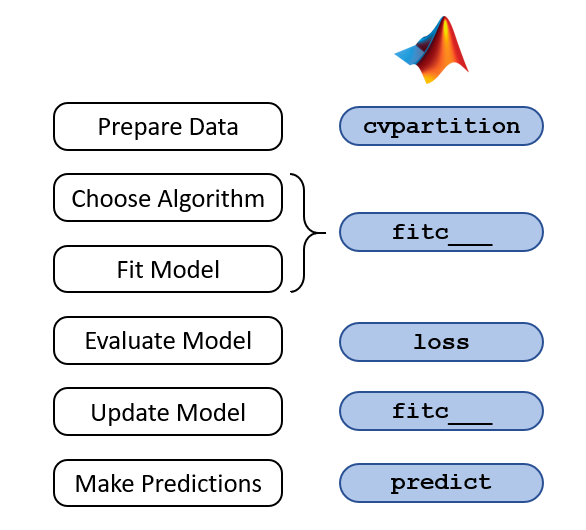

### Demo: Use biometric and lab data for heart disease classification

#### Import and Prepare Data

Load the example data and extract numerical predictors.

heartData = readtable("data/heartDiseaseData.csv");
heartData = convertvars(heartData,12:22,"categorical");
heartDataNum = heartData(:,[1:11 22]);

Partition into training and test sets.

rng(1234)
pt = cvpartition(heartData.HeartDisease,"Holdout",0.2);
hdTrainNum = heartDataNum(training(pt),:);
hdTestNum = heartDataNum(~training(pt),:);
hdTrain = heartData(training(pt),:);
hdTest = heartData(~training(pt),:);

#### Interactive tool: Classification Learner App

APPS --> Classification Learner --> New Session --> Import data from workspace

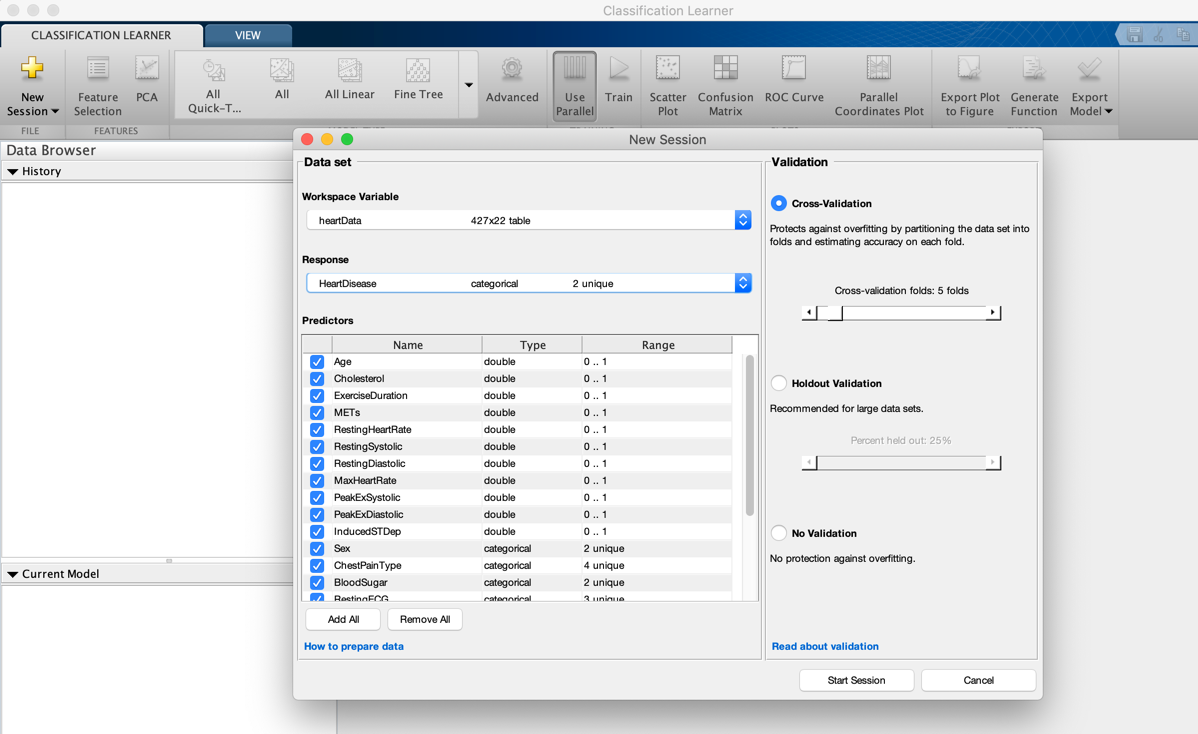

**kNN (k-Nearest-Neighbor) Classification**

mdl = fitcknn(hdTrainNum,"HeartDisease");
resubLoss(mdl)

ans = 0

loss(mdl,hdTestNum)

ans = 0.3413

Visualize prediction accuracy.

HDpred = predict(mdl,hdTestNum);
HDtrue = hdTestNum.HeartDisease;
[cm,grp] = confusionmat(HDtrue,HDpred)

cm =     19    19
    10    37


grp = 2×1 categorical array
     false 
     true 


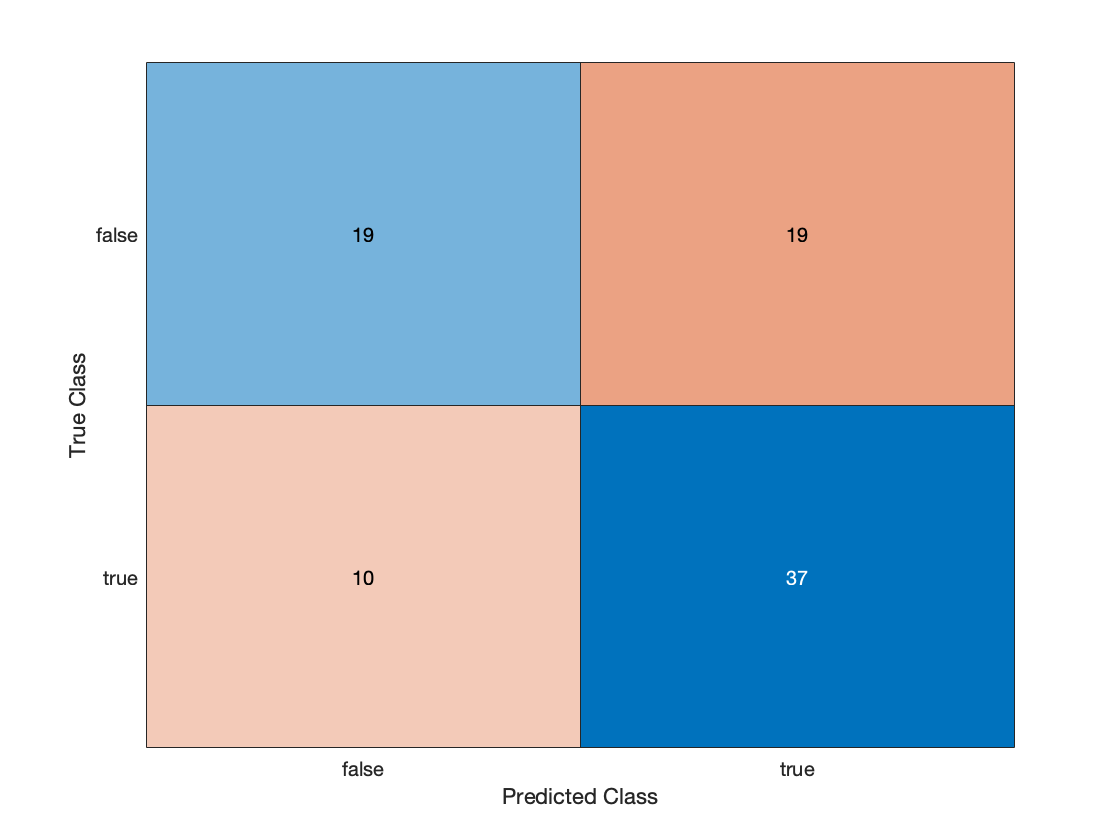

confusionchart(HDtrue,HDpred);

Increase the number of neighbors.

mdl.NumNeighbors = 5;
resubLoss(mdl)

ans = 0.2222

loss(mdl,hdTestNum)

ans = 0.2471

Change the distance weighting option.

`mdl.DistanceWeight = "squaredinverse";`

**Decision Trees**

Fit and evaluate a decision tree model with default settings.

mdl = fitctree(hdTrainNum,"HeartDisease");
resubLoss(mdl)
loss(mdl,hdTestNum)
view(mdl,"mode","graph")

Prune the tree.

mdl = prune(mdl,"Level",3);
resubLoss(mdl)

ans = 0.0789

loss(mdl,hdTestNum)

ans = 0.2706

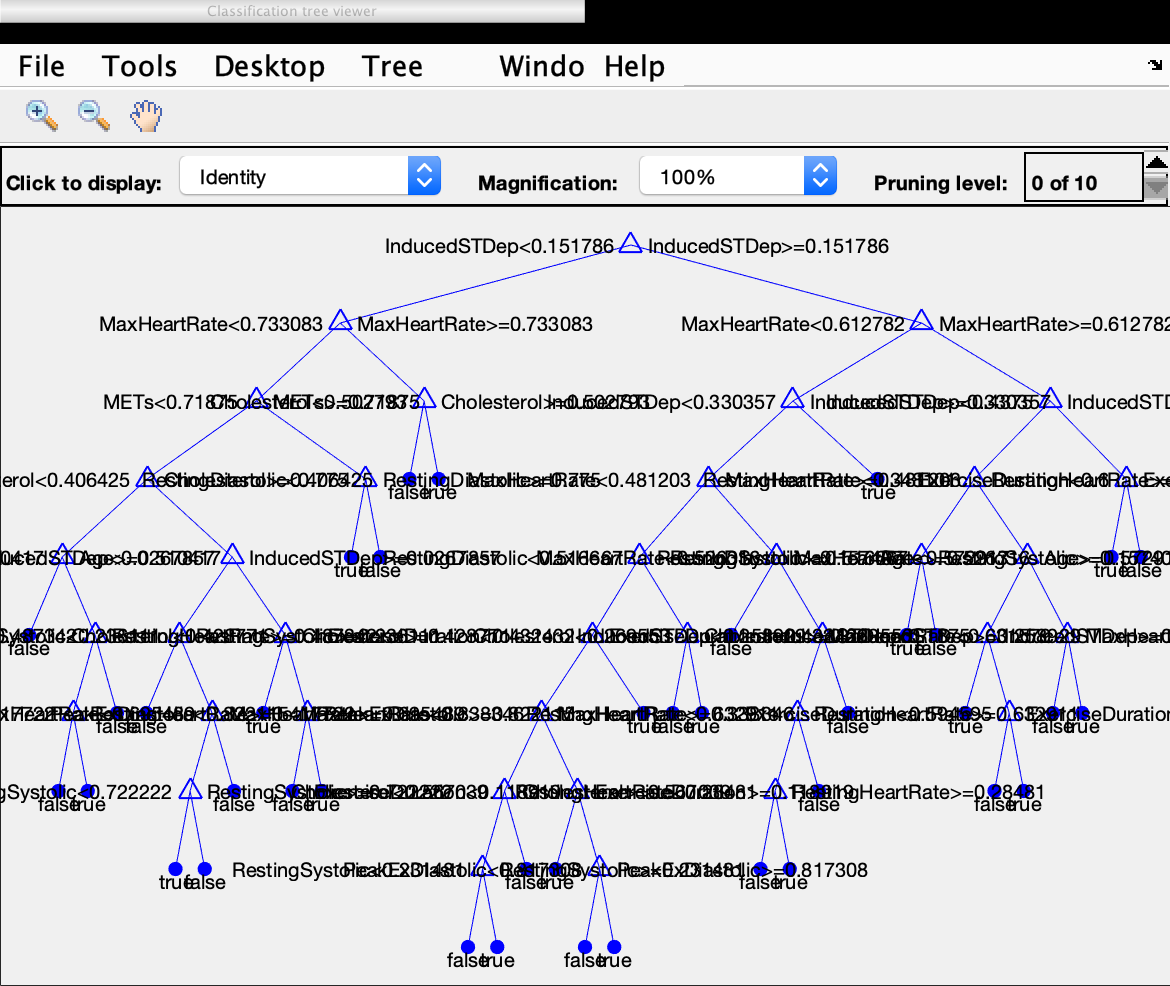

view(mdl,"mode","graph")

Use a mix of numeric and categorical predictors.

mdl = fitctree(hdTrain,"HeartDisease");
resubLoss(mdl)

ans = 0.1404

loss(mdl,hdTest)

ans = 0.1883

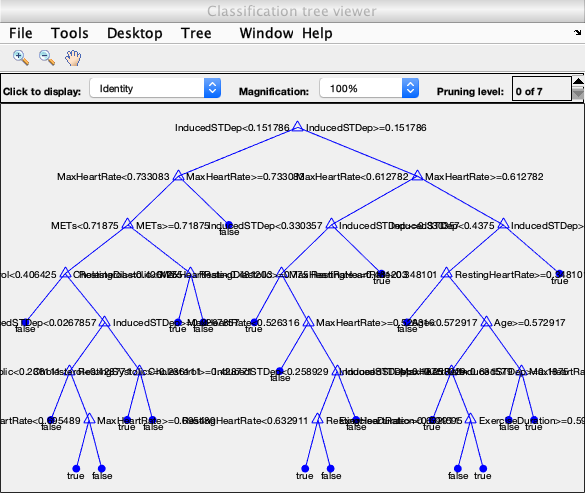

mdl = prune(mdl,"Level",3);

resubLoss(mdl)
loss(mdl,hdTest)

**Discriminant Analysis**

Fit and evaluate a linear discriminant model with default settings.

mdl = fitcdiscr(hdTrainNum,"HeartDisease");
resubLoss(mdl)

ans = 0.0526

loss(mdl,hdTestNum)

ans = 0.2471

Use a quadratic boundary.

mdl = fitcdiscr(hdTrainNum,"HeartDisease","DiscrimType","quadratic");
resubLoss(mdl)

ans = 0.0994

loss(mdl,hdTestNum)

ans = 0.2118

**SVM (Support Vector Machine)**

Fit and evaluate an SVM with default settings.

mdl = fitcsvm(hdTrainNum,"HeartDisease");
resubLoss(mdl)
loss(mdl,hdTestNum)

Use a nonlinear kernel. 

mdl = fitcsvm(hdTrainNum,"HeartDisease","KernelFunction","gaussian");
resubLoss(mdl)
loss(mdl,hdTestNum)

Use a mix of numeric and categorical predictors.

mdl = fitcsvm(hdTrain,"HeartDisease");
resubLoss(mdl)
loss(mdl,hdTest)

Use a nonlinear kernel.

mdl = fitcsvm(hdTrain,"HeartDisease","KernelFunction","gaussian");
resubLoss(mdl)
loss(mdl,hdTest)

**Naive Bayes**

Fit and evaluate a Naive Bayes model with default settings.

mdl = fitcnb(hdTrainNum,"HeartDisease");
resubLoss(mdl)
loss(mdl,hdTestNum)

Use kernel smoothing instead of normal distributions.

mdl = fitcnb(hdTrainNum,"HeartDisease","DistributionNames","kernel");
resubLoss(mdl)
loss(mdl,hdTestNum)

Use a mix of numeric and categorical predictors.

mdl = fitcnb(hdTrain,"HeartDisease");
resubLoss(mdl)
loss(mdl,hdTest)
confusionchart(hdTest.HeartDisease,predict(mdl,hdTest));

close all; clear; clc

**Multiclass SVM**

Load and partition multiclass heart disease data set.

heartDataMulti = readtable("data/heartDiseaseDataMulticlass.csv");
heartDataMulti = convertvars(heartDataMulti,12:22,"categorical");
tabulate(heartDataMulti.HeartDisease)

rng(1234)
pt = cvpartition(heartDataMulti.HeartDisease,"Holdout",0.2,...
    'Stratify',true)
hdMTrain = heartDataMulti(training(pt),:);
hdMTest = heartDataMulti(~training(pt),:);
hdMTrainNum = heartDataMulti(training(pt),[1:11 22]);
hdMTestNum = heartDataMulti(~training(pt),[1:11 22]);

Linear SVM

mdl = fitcecoc(hdMTrainNum,"HeartDisease");
linResubLoss = resubLoss(mdl)
linTestLoss = loss(mdl,hdMTestNum)

  Value    Count   Percent
      0      191     44.73%
      1       87     20.37%
      2       56     13.11%
      3       66     15.46%
      4       27      6.32%


Gaussian SVM

template = templateSVM("KernelFunction","gaussian");
mdl = fitcecoc(hdMTrainNum,"HeartDisease","Learners",template);
gaussResubLoss = resubLoss(mdl)

pt = Hold-out cross validation partition
   NumObservations: 427
       NumTestSets: 1
         TrainSize: 342
          TestSize: 85

gaussTestLoss = loss(mdl,hdMTestNum)

Linear SVM with mixed predictors

mdl = fitcecoc(hdMTrain,"HeartDisease");
mixedLinResubLoss = resubLoss(mdl)
mixedLinTestLoss = loss(mdl,hdMTest)

Gaussian SVM with mixed predictors

template = templateSVM("KernelFunction","gaussian");
mdl = fitcecoc(hdMTrain,"HeartDisease","Learners",template);

linResubLoss = 0.4912

mixedGaussResubLoss = resubLoss(mdl)

linTestLoss = 0.4949

mixedGaussTestLoss = loss(mdl,hdMTest)

Inspect the classification performance

confusionchart(hdMTest.HeartDisease,predict(mdl,hdMTest),...
    'Normalization','row-normalized','RowSummary','row-normalized');

#### Alternative: Ensemble Method (more on this later)

N = sum(training(pt));

gaussResubLoss = 0.4444

t = templateTree('MaxNumSplits',N);

gaussTestLoss = 0.5062

rusTree = fitcensemble(hdMTrain,"HeartDisease",'Method','RUSBoost', ...
    'NumLearningCycles',1000,'Learners',t,'LearnRate',0.1,'nprint',100);

**Inspect the classification performance**

plot(loss(rusTree,hdMTest,"HeartDisease",'mode','cumulative'));
confusionchart(hdMTest.HeartDisease,predict(rusTree,hdMTest),...

mixedLinResubLoss = 0.3977

    'Normalization','row-normalized','RowSummary','row-normalized');

mixedLinTestLoss = 0.5377

## Improving Predictive Models

### Cross Validation

Create 7-fold cross-validation partition.

heartData = readtable("data/heartDiseaseData.csv");
heartData = convertvars(heartData,12:22,"categorical");
heartDataNum = heartData(:,[1:11 22]);

mixedGaussResubLoss = 0.1667

part = cvpartition(heartDataNum.HeartDisease,"KFold",7);

mixedGaussTestLoss = 0.5303

Train kNN and DA models.

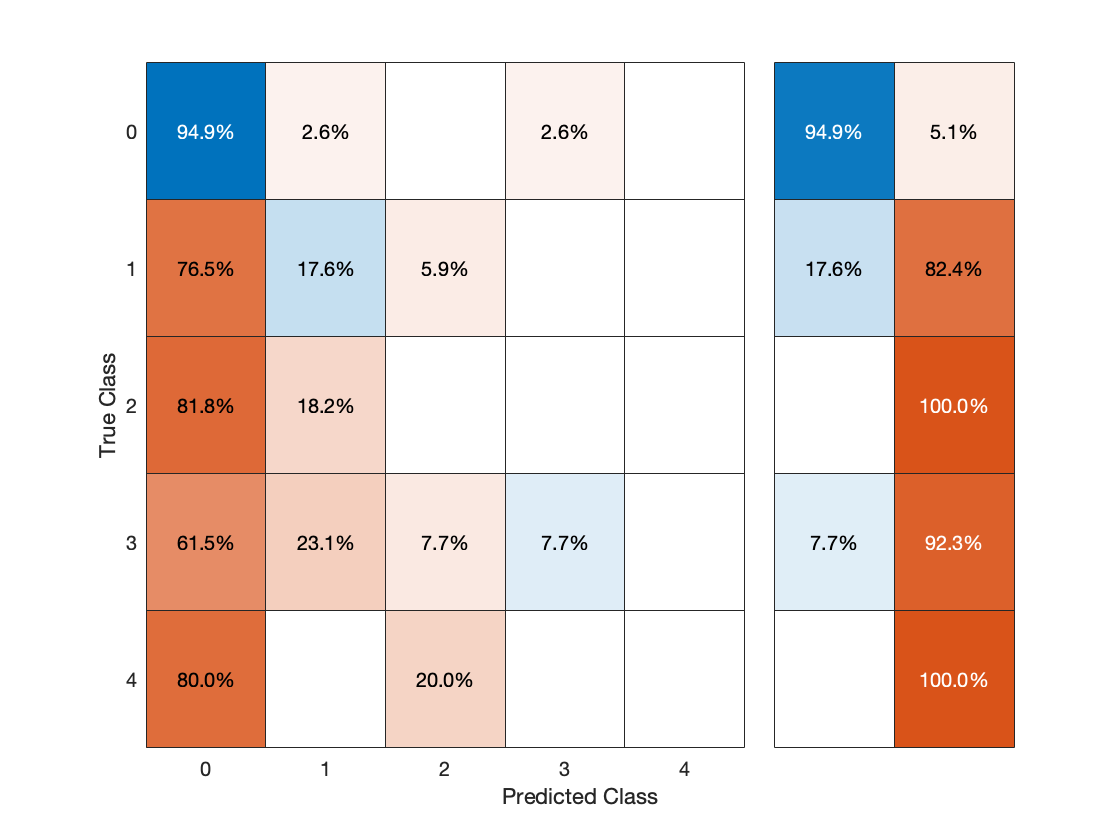

% kNN
mdlKnn = fitcknn(heartDataNum,"HeartDisease","NumNeighbors",5,"CVPartition",part);
lossKnn = kfoldLoss(mdlKnn);


% Discriminant analysis
mdlDa = fitcdiscr(heartDataNum,"HeartDisease","CVPartition",part);
lossDa = kfoldLoss(mdlDa);

Display the results.

KFoldLoss = [lossKnn;lossDa];
results = table(KFoldLoss);

Training RUSBoost...
Grown weak learners: 100
Grown weak learners: 200
Grown weak learners: 300
Grown weak learners: 400
Grown weak learners: 500
Grown weak learners: 600
Grown weak learners: 700
Grown weak learners: 800
Grown weak learners: 900
Grown weak learners: 1000


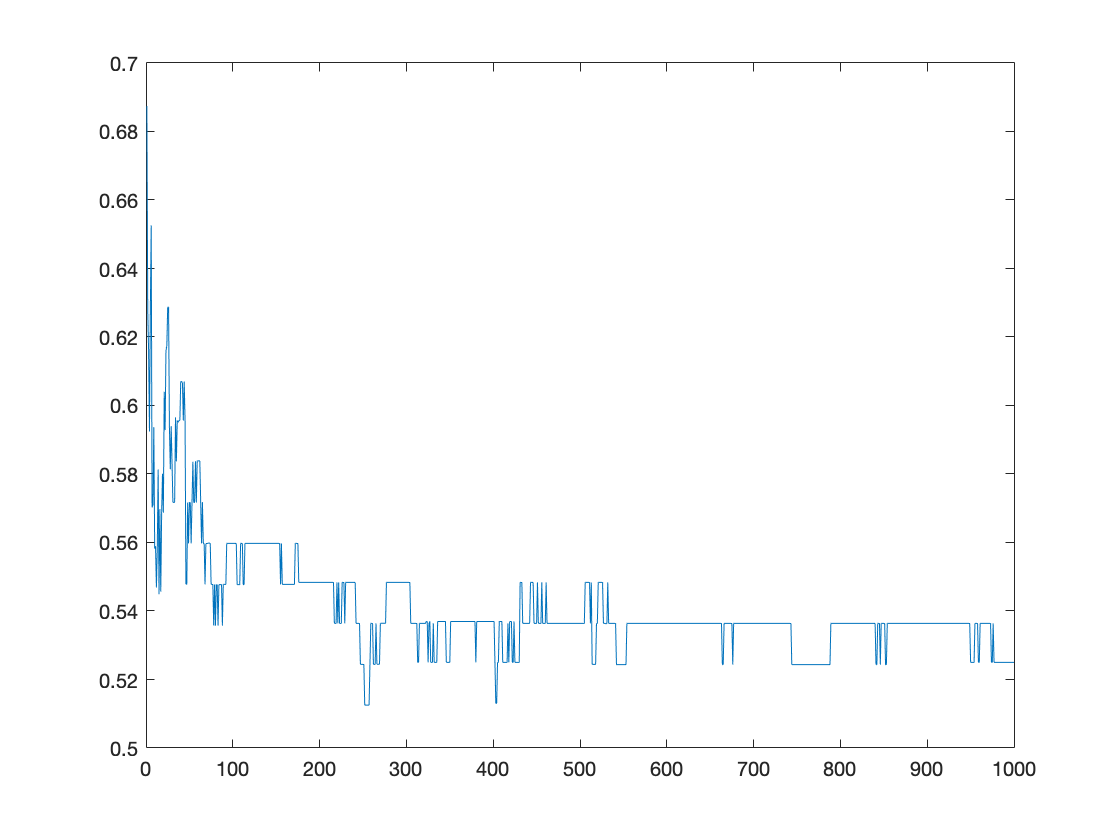

results.Properties.RowNames = ["kNN" "Discriminant Analysis"];
disp("Seven-fold cross-validated results")
disp(results)

### Hyperparameter Optimization

Optimize all hyperparameters kNN classifier for multiclass numeric heart disease data.

Set optimization options.

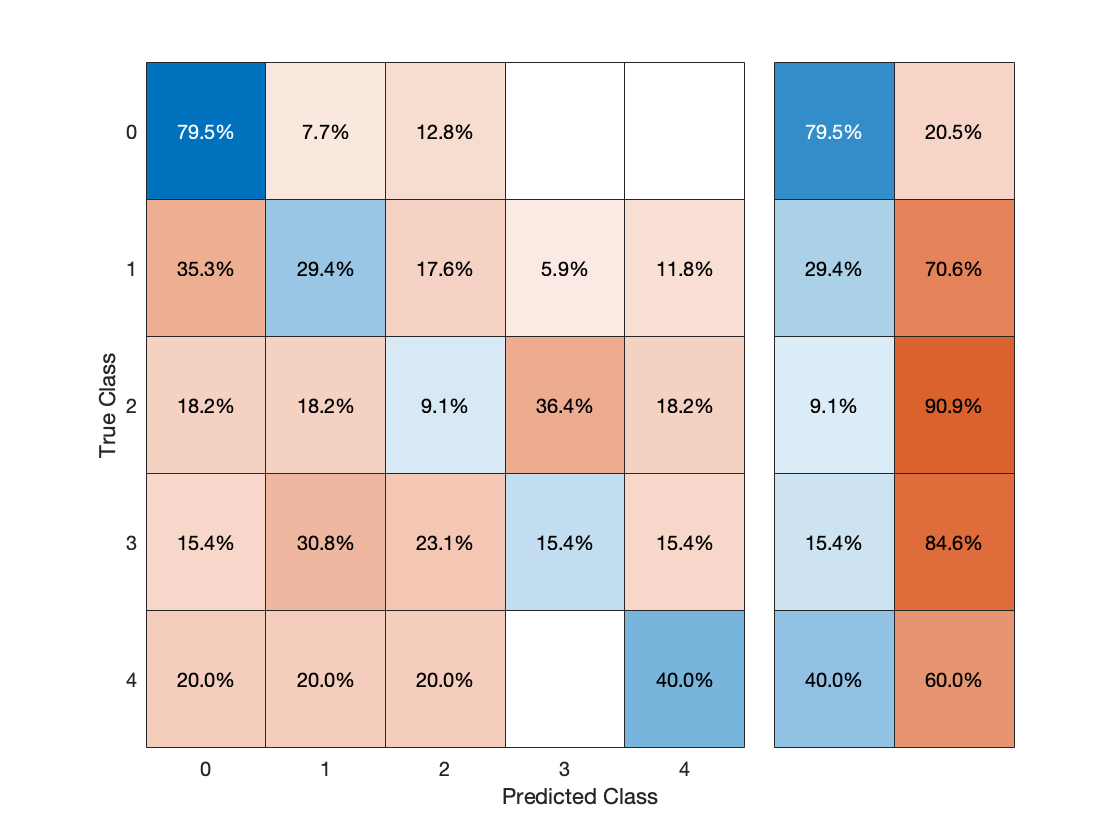

cvpt = cvpartition(hdMTrainNum.HeartDisease,"KFold",10);
opt = struct("CVPartition",cvpt,"MaxObjectiveEvaluations",10);

Optimize hyperparameters.

mdl = fitcknn(hdMTrainNum,"HeartDisease",...
    "OptimizeHyperparameters","all","HyperparameterOptimizationOptions",opt);

Calculate loss.

trainLossOpt = resubLoss(mdl)
testLossOpt = loss(mdl,hdMTestNum)

### PCA

Extract response and numerical data.

HD = heartDataNum.HeartDisease;
numData = heartDataNum{:,1:end-1};

Perform PCA.

[pcs,scrs,~,~,pexp] = pca(numData);
pareto(pexp)

Visualize principal components.

varNames = heartDataNum.Properties.VariableNames(1:end-1);
heatmap(abs(pcs(:,1:8)),"YDisplayLabels",varNames,"Colormap",parula);

Fit Naive Bayes model to original data.

mdlOrig = fitcnb(numData,HD,"DistributionNames","kernel","KFold",10);
lossOrig = kfoldLoss(mdlOrig)

Seven-fold cross-validated results


Fit Naive Bayes model to reduced data.

numDataPart = scrs(:,1:5);

                             KFoldLoss
                             _________

    kNN                       0.29977 
    Discriminant Analysis     0.27635 



mdlPart = fitcnb(numDataPart,HD,"DistributionNames","kernel","KFold",10);
lossPart = kfoldLoss(mdlPart)

### Sequential Feature Selection

Create 10-fold partition of mixed heart disease data set.

HD = heartData.HeartDisease;
rng(1234)
cvpt = cvpartition(HD,"KFold",10);

Make dummy variables for categorical predictors (one-hot encoding).

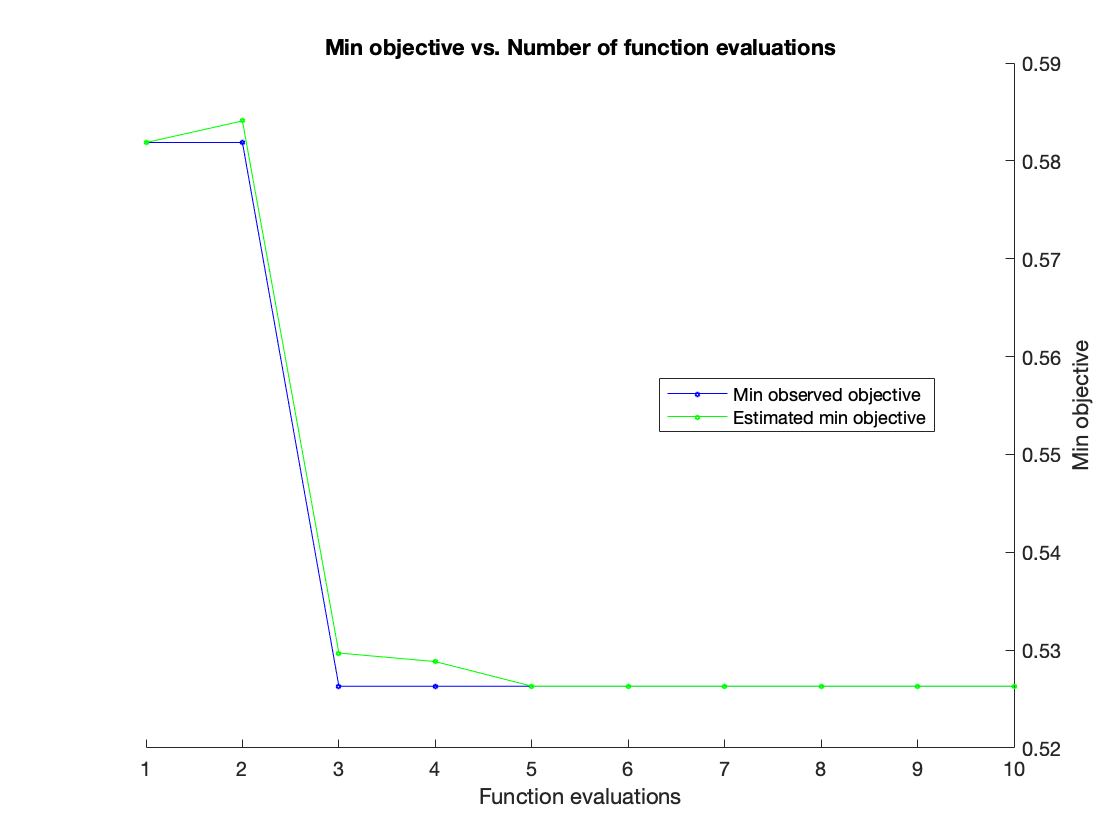

|==================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance | DistanceWeig-|     Exponent |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | ht           |              |              |
|==================================================================================================================================================|
|    1 | Best   |     0.58187 |     0.64976 |     0.58187 |     0.58187 |            7 |    chebychev |      inverse |            - |         true |
|    2 | Accept |     0.63743 |      0.3406 |     0.58187 |     0.58408 |            2 |    euclidean |        equal |            - |        false |
|    3 | Best   |     0.52632 |     0.47776 |     0.52632 |      0.5297 |           76 |    minkowski |   

T = splitvars(convertvars(heartData(:,1:end-1),vartype("categorical"),@dummyvar));
X = T{:,:};

Xnames = T.Properties.VariableNames;

Fit Naive Bayes model to the full data.

dists = [repmat("kernel",1,11),repmat("mvmn",1,10)];

trainLossOpt = 0

mdlFull = fitcnb(heartData,"HeartDisease","DistributionNames",dists,"CVPartition",cvpt);

testLossOpt = 0.5426

Perform sequential feature selection.

rng(1234)
fmodel = @(X,y) fitcnb(X,y,"DistributionNames","kernel");
ferror = @(Xtrain,ytrain,Xtest,ytest) nnz(predict(fmodel(Xtrain,ytrain),Xtest) ~= ytest);
toKeep = sequentialfs(ferror,X,HD,"cv",cvpt,"options",statset("Display","iter"));

Which variables are in the final model?

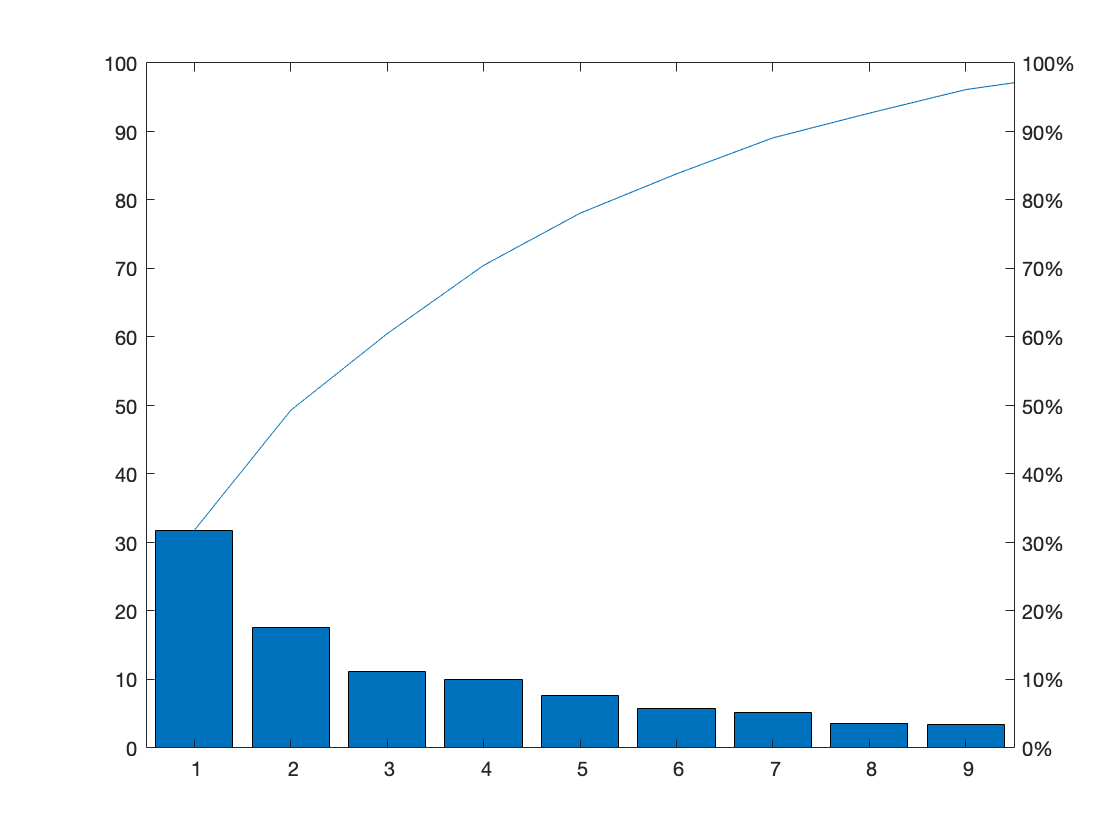

Xnames(toKeep)

Fit NB model to the selected variables.

mdlPart = fitcnb(X(:,toKeep),HD,"DistributionNames","kernel","CVPartition",cvpt);

Display loss values.

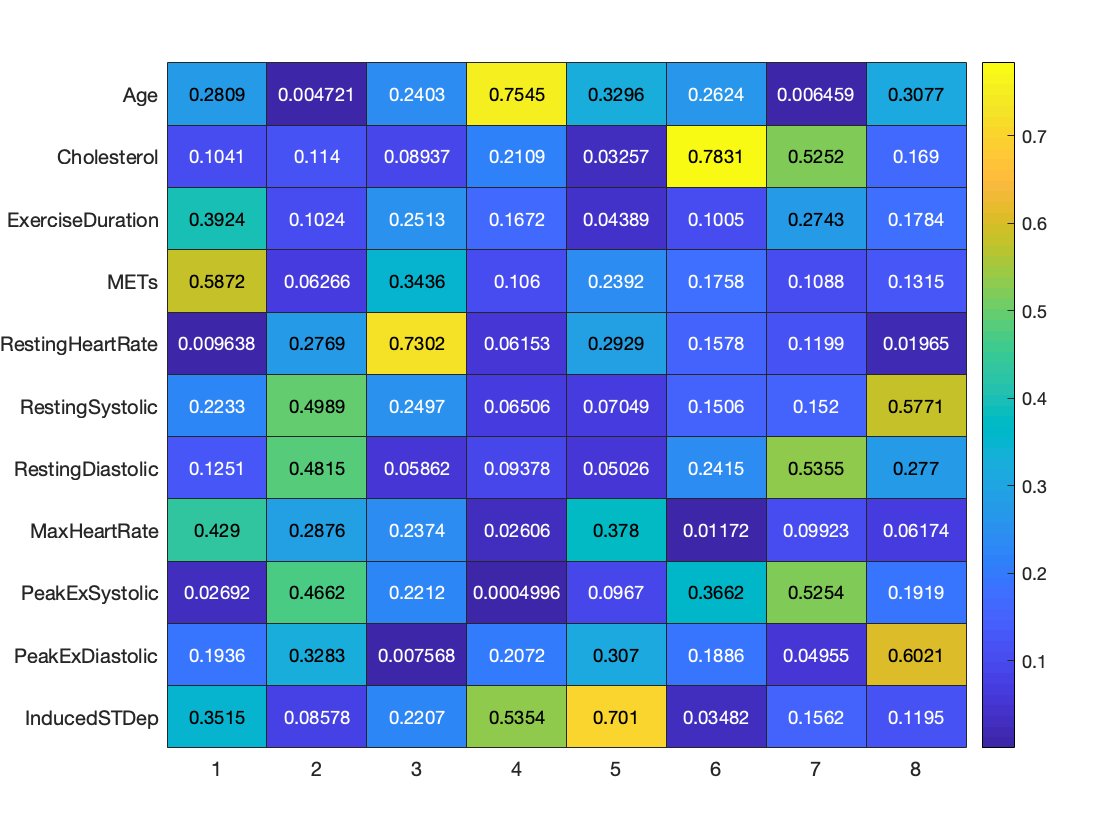

lossFull = kfoldLoss(mdlFull)

lossPart = kfoldLoss(mdlPart)

### Ensemble Learning

rng(1234)
cvpt = cvpartition(heartData.HeartDisease,"KFold",10);

lossOrig = 0.2740

Train a single decision tree.

mdl = fitctree(heartData,"HeartDisease","CVPartition",cvpt);
singleTLoss = kfoldLoss(mdl)

Build an ensemble of bagged trees.

rng(1234)

lossPart = 0.2529

mdl = fitcensemble(heartData,"HeartDisease","Method","Bag",...
    "Learners",'Tree',"NumLearningCycles",50,"CVPartition",cvpt);
bagTLoss = kfoldLoss(mdl)

## **Regression **

clear; clc

### Demo: Vehicle Fuel Economy

Fuel economy is a key part of a motor vehicle’s technical specifications, and it can be an important consideration for many people when choosing a vehicle to purchase. A vehicle's fuel economy is, in turn, impacted by many of the vehicle's other specifications, such as the size of the vehicle and the size of the engine. It would be useful for an automobile manufacturer to be able to predict fuel economy based these other specifications.

Because fuel economy is a continuous measure, the prediction model will be a *regression* model, with the various technical specifications as the predictor variables and fuel economy as the response. 

#### Load and Prepare Data

carData = readtable("data/carData.csv");
carData = convertvars(carData,vartype("cellstr"),"categorical");
carData
cvpt = cvpartition(carData.FuelEcon,"HoldOut",0.33);
carTrain = carData(training(cvpt),:);
carTest = carData(~training(cvpt),:);

### Linear Regression Models

Linear regression is one of the simplest—but most powerful—regression techniques. It is a parametric regression technique in which the response is modeled as some known formula given in terms of the predictor variables.

`mdl = fitlm(data,"modelspec")`

Plot fuel economy vs engine displacement.

scatter(carData.EngDisp,carData.FuelEcon,".")

Fit a single-predictor linear model of fuel economy.

mdl = fitlm(carTrain.EngDisp,carTrain.FuelEcon);

Add model to the plot.

x = [min(carData.EngDisp);max(carData.EngDisp)];
y = predict(mdl,x);
hold on
plot(x,y)

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 14, criterion value 0.234192
Step 2, added column 8, criterion value 0.222482
Step 3, added column 11, criterion value 0.213115
Step 4, added column 17, criterion value 0.208431
Step 5, added column 25, criterion value 0.203747
Step 6, added column 2, criterion value 0.199063
Step 7, added column 12, criterion value 0.194379
Step 8, added column 31, criterion value 0.185012
Step 9, added column 1, criterion value 0.18267
Final columns included:  1 2 8 11 12 14 17 25 31 


hold off
xlabel("Engine displacement (L)")
ylabel("Fuel economy (L/100km)")

ans = 1×9 cell array
    {'Age'}    {'Cholesterol'}    {'MaxHeartRate'}    {'InducedSTDep'}    {'Sex_1'}    {'ChestPainType_1'}    {'ChestPainType_4'}    {'NitratesUsed_1'}    {'ExInducedAngina_1'}


Predict fuel economy at test predictor values.

econpred = predict(mdl,carTest.EngDisp);

Plot predicted and actual responses vs. observation number.

plot(carTest.FuelEcon,".")

lossFull = 0.2131

hold on

lossPart = 0.1827

plot(econpred,"*")
hold off
xlabel("Observation number")
ylabel("Fuel economy")

Plot predicted and actual responses against each other.

scatter(carTest.FuelEcon,econpred,".")
% add diagonal line

singleTLoss = 0.2787

hold on
plot([0 30],[0 30],"k:")
hold off
xlabel("Actual fuel economy")
ylabel("Predicted fuel economy")

bagTLoss = 0.2272

Plot distribution of errors.

err = carTest.FuelEcon - econpred;
histogram(err)
xlabel("Prediction error")
MSE = mean(err.^2)

Plot distribution of percentage errors.

percerr = 100*err./carTest.FuelEcon;
histogram(percerr)
xlabel("Prediction percentage error")
MAPE = mean(abs(percerr))

close all

### Multivariate Linear Models

Fit a multivariate linear model of fuel economy.

mdl = fitlm(carTrain);

Predict fuel economy at test predictor values.

econpred = predict(mdl,carTest);

Compare predicted and actual responses.

evaluatefit(carTest.FuelEcon,econpred,"Linear Model")

Fit and evaluate a multivariate linear model with robust fitting.

mdl = fitlm(carTrain,"RobustOpts","cauchy");
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,"Linear Model (robust)")

### Stepwise Fitting

Perform a stepwise linear fit of fuel economy.

mdl = stepwiselm(carTrain,'NSteps',8);

Predict fuel economy at test predictor values.

econpred = predict(mdl,carTest);

Compare predicted and actual responses.

evaluatefit(carTest.FuelEcon,econpred,"Stepwise")

Change criterion and limit to linear models.

mdl = stepwiselm(carTrain,"Criterion","aic","Upper","linear");
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,"Stepwise with AIC")

### SVMs

Fit an SVM regression model of fuel economy.

mdl = fitrsvm(carTrain,"FuelEcon");

Predict fuel economy at test predictor values.

econpred = predict(mdl,carTest);

Compare predicted and actual responses.

evaluatefit(carTest.FuelEcon,econpred,"Linear SVM")

Standardize variables.

`mdl = fitrsvm(carTrain,"FuelEcon","Standardize",true);`

Try a different kernel.

`mdl = fitrsvm(carTrain,"FuelEcon","KernelFunction","gaussian");`

### Decision Trees

Fit a decision tree regression model of fuel economy.

mdl = fitrtree(carTrain,"FuelEcon");

Predict fuel economy at test predictor values.

econpred = predict(mdl,carTest);

Compare predicted and actual responses

evaluatefit(carTest.FuelEcon,econpred,"Tree")

Prune the tree.

mdl = prune(mdl,"Level",10);
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,"Pruned tree")

Set minimum leaf size.

mdl = fitrtree(carTrain,"FuelEcon","MinLeafSize",5);
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,"Tree with leaf limit")

### Gaussian Process Regression

Fit a Gaussian process model of fuel economy.

mdl = fitrgp(carTrain,"FuelEcon");

Predict fuel economy at test predictor values.

[econpred,~,epint] = predict(mdl,carTest);

Compare predicted and actual responses.

evaluatefit(carTest.FuelEcon,econpred,"GPR")

**Local function:** `evaluatefit`

function evaluatefit(y,ypred,name)
figure
% Plot against observation number
subplot(2,2,1)
plot(y,".")
hold on
plot(ypred,".")
title(name)
xlabel("Observation number")
ylabel("Fuel economy")

% Plot predicted and actual against each other
subplot(2,2,2)
scatter(y,ypred,".")
% Add 45-degree line
xl = xlim;
hold on
plot(xl,xl,"k:")
title(name)
xlabel("Actual fuel economy")
ylabel("Predicted fuel economy")

% Distribution of errors
subplot(2,2,3)
err = y - ypred;
MSE = mean(err.^2,"omitnan");
histogram(err)
title(["MSE = ",num2str(MSE,4)])
xlabel("Prediction error")

% Distribution of percentage errors
subplot(2,2,4)
err = 100*err./y;
MAPE = mean(abs(err),"omitnan");
histogram(err)
title(["Mean Abs. Perc. Error = ",num2str(MAPE,4)])
xlabel("Prediction percentage error")
end